EKF - Single feature tracking

Step 1: Connect UART ports.

ports = serialportlist

ports = 1×28 string array
    "/dev/cu.FreeBuds3"    "/dev/tty.FreeBuds3"    "/dev/cu.Bluetooth-Incoming-Port"    "/dev/tty.Bluetooth-Incoming-Port"    "/dev/cu.usbserial-0001"    "/dev/tty.usbserial-0001"    "/dev/cu.SLAB_USBtoUART"    "/dev/tty.SLAB_USBtoUART"    "/dev/cu.SLAB_USBtoUART13"    "/dev/tty.SLAB_USBtoUART13"    "/dev/cu.SLAB_USBtoUART5"    "/dev/tty.SLAB_USBtoUART5"    "/dev/cu.SLAB_USBtoUART9"    "/dev/tty.SLAB_USBtoUART9"    "/dev/cu.usbserial-4"    "/dev/tty.usbserial-4"    "/dev/cu.usbserial-6"    "/dev/tty.usbserial-6"    "/dev/cu.usbserial-10"    "/dev/tty.usbserial-10"    "/dev/cu.SLAB_USBtoUART11"    "/dev/tty.SLAB_USBtoUART11"    "/dev/cu.usbserial-8"    "/dev/tty.usbserial-8"    "/dev/cu.SLAB_USBtoUART7"    "/dev/tty.SLAB_USBtoUART7"    "/dev/cu.usbserial-12"    "/dev/tty.usbserial-12"


openmv1=0;
openmv2=0;
openmv3=0;
openmv4=0;
openmv5=0;
openmv6=0;

openmv1 = serialport('/dev/tty.usbserial-0001',115200)

openmv1 =   Serialport with properties:

                 Port: "/dev/tty.usbserial-0001"
             BaudRate: 115200
    NumBytesAvailable: 0

  Show all properties, functions


openmv2 = serialport('/dev/tty.usbserial-4',115200)

openmv2 =   Serialport with properties:

                 Port: "/dev/tty.usbserial-4"
             BaudRate: 115200
    NumBytesAvailable: 0

  Show all properties, functions


openmv3 = serialport('/dev/tty.usbserial-6',115200)

openmv3 =   Serialport with properties:

                 Port: "/dev/tty.usbserial-6"
             BaudRate: 115200
    NumBytesAvailable: 0

  Show all properties, functions


openmv4 = serialport('/dev/tty.usbserial-8',115200)

openmv4 =   Serialport with properties:

                 Port: "/dev/tty.usbserial-8"
             BaudRate: 115200
    NumBytesAvailable: 0

  Show all properties, functions


openmv5 = serialport('/dev/tty.usbserial-10',115200)

openmv5 =   Serialport with properties:

                 Port: "/dev/tty.usbserial-10"
             BaudRate: 115200
    NumBytesAvailable: 0

  Show all properties, functions


openmv6 = serialport('/dev/tty.usbserial-12',115200)

openmv6 =   Serialport with properties:

                 Port: "/dev/tty.usbserial-12"
             BaudRate: 115200
    NumBytesAvailable: 0

  Show all properties, functions


Step 2: Intrinisc parameters

openmv1.write('INT','string')
openmv2.write('INT','string')
openmv3.write('INT','string')
openmv4.write('INT','string')
openmv5.write('INT','string')
openmv6.write('INT','string')

camID1 = extractAfter(openmv1.readline(),'0')

camID1 = "3"

camID2 = extractAfter(openmv2.readline(),'0')

camID2 = "1"

camID3 = extractAfter(openmv3.readline(),'0')

camID3 = "2"

camID4 = extractAfter(openmv4.readline(),'0')

camID4 = "6"

camID5 = extractAfter(openmv5.readline(),'0')

camID5 = "4"

camID6 = extractAfter(openmv6.readline(),'0')

camID6 = "5"


filepath1_1 = ['/Users/ferialmeyer/Documents/Zak - UCT Stuff/MATLAB INTRINSIC PARAMS/CAM',num2str(camID1),'/CAM',num2str(camID1),'Params_GRAYSCALE.mat'];
filepath1_2 = ['/Users/ferialmeyer/Documents/Zak - UCT Stuff/MATLAB INTRINSIC PARAMS/CAM',num2str(camID1),'/CAM',num2str(camID1),'Params_RGB.mat'];
file1_1 = load(filepath1_1);
file1_2 = load(filepath1_2);
cInt1 = file1_1.cameraParams;
calibInt1 = file1_2.cameraParams;

filepath1_1 = ['/Users/ferialmeyer/Documents/Zak - UCT Stuff/MATLAB INTRINSIC PARAMS/CAM',num2str(camID2),'/CAM',num2str(camID2),'Params_GRAYSCALE.mat'];
filepath1_2 = ['/Users/ferialmeyer/Documents/Zak - UCT Stuff/MATLAB INTRINSIC PARAMS/CAM',num2str(camID2),'/CAM',num2str(camID2),'Params_RGB.mat'];
file1_1 = load(filepath1_1);
file1_2 = load(filepath1_2);
cInt2 = file1_1.cameraParams;
calibInt2 = file1_2.cameraParams;

filepath1_1 = ['/Users/ferialmeyer/Documents/Zak - UCT Stuff/MATLAB INTRINSIC PARAMS/CAM',num2str(camID1),'/CAM',num2str(camID1),'Params_GRAYSCALE.mat'];
filepath1_2 = ['/Users/ferialmeyer/Documents/Zak - UCT Stuff/MATLAB INTRINSIC PARAMS/CAM',num2str(camID1),'/CAM',num2str(camID1),'Params_RGB.mat'];
file1_1 = load(filepath1_1);
file1_2 = load(filepath1_2);
cInt3 = file1_1.cameraParams;
calibInt3 = file1_2.cameraParams;

filepath1_1 = ['/Users/ferialmeyer/Documents/Zak - UCT Stuff/MATLAB INTRINSIC PARAMS/CAM',num2str(camID2),'/CAM',num2str(camID2),'Params_GRAYSCALE.mat'];
filepath1_2 = ['/Users/ferialmeyer/Documents/Zak - UCT Stuff/MATLAB INTRINSIC PARAMS/CAM',num2str(camID2),'/CAM',num2str(camID2),'Params_RGB.mat'];
file1_1 = load(filepath1_1);
file1_2 = load(filepath1_2);
cInt4 = file1_1.cameraParams;
calibInt4 = file1_2.cameraParams;

filepath1_1 = ['/Users/ferialmeyer/Documents/Zak - UCT Stuff/MATLAB INTRINSIC PARAMS/CAM',num2str(camID1),'/CAM',num2str(camID1),'Params_GRAYSCALE.mat'];
filepath1_2 = ['/Users/ferialmeyer/Documents/Zak - UCT Stuff/MATLAB INTRINSIC PARAMS/CAM',num2str(camID1),'/CAM',num2str(camID1),'Params_RGB.mat'];
file1_1 = load(filepath1_1);
file1_2 = load(filepath1_2);
cInt5 = file1_1.cameraParams;
calibInt5 = file1_2.cameraParams;

filepath1_1 = ['/Users/ferialmeyer/Documents/Zak - UCT Stuff/MATLAB INTRINSIC PARAMS/CAM',num2str(camID2),'/CAM',num2str(camID2),'Params_GRAYSCALE.mat'];
filepath1_2 = ['/Users/ferialmeyer/Documents/Zak - UCT Stuff/MATLAB INTRINSIC PARAMS/CAM',num2str(camID2),'/CAM',num2str(camID2),'Params_RGB.mat'];
file1_1 = load(filepath1_1);
file1_2 = load(filepath1_2);
cInt6 = file1_1.cameraParams;
calibInt6 = file1_2.cameraParams;

cInt1

cInt1 =   cameraParameters with properties:

   Camera Intrinsics
                         Intrinsics: [1×1 cameraIntrinsics]

   Camera Extrinsics
                  PatternExtrinsics: [20×1 rigidtform3d]

   Accuracy of Estimation
              MeanReprojectionError: 0.2039
                 ReprojectionErrors: [35×2×20 double]
                  ReprojectedPoints: [35×2×20 double]

   Calibration Settings
                        NumPatterns: 20
                  DetectedKeypoints: [35×20 logical]
                        WorldPoints: [35×2 double]
                         WorldUnits: 'millimeters'
                       EstimateSkew: 0
    NumRadialDistortionCoefficients: 3
       EstimateTangentialDistortion: 0


cInt2

cInt2 =   cameraParameters with properties:

   Camera Intrinsics
                         Intrinsics: [1×1 cameraIntrinsics]

   Camera Extrinsics
                  PatternExtrinsics: [18×1 rigidtform3d]

   Accuracy of Estimation
              MeanReprojectionError: 0.2189
                 ReprojectionErrors: [48×2×18 double]
                  ReprojectedPoints: [48×2×18 double]

   Calibration Settings
                        NumPatterns: 18
                  DetectedKeypoints: [48×18 logical]
                        WorldPoints: [48×2 double]
                         WorldUnits: 'millimeters'
                       EstimateSkew: 0
    NumRadialDistortionCoefficients: 2
       EstimateTangentialDistortion: 0


calibInt1

calibInt1 =   cameraParameters with properties:

   Camera Intrinsics
                         Intrinsics: [1×1 cameraIntrinsics]

   Camera Extrinsics
                  PatternExtrinsics: [14×1 rigidtform3d]

   Accuracy of Estimation
              MeanReprojectionError: 0.1221
                 ReprojectionErrors: [35×2×14 double]
                  ReprojectedPoints: [35×2×14 double]

   Calibration Settings
                        NumPatterns: 14
                  DetectedKeypoints: [35×14 logical]
                        WorldPoints: [35×2 double]
                         WorldUnits: 'millimeters'
                       EstimateSkew: 0
    NumRadialDistortionCoefficients: 3
       EstimateTangentialDistortion: 0


calibInt2

calibInt2 =   cameraParameters with properties:

   Camera Intrinsics
                         Intrinsics: [1×1 cameraIntrinsics]

   Camera Extrinsics
                  PatternExtrinsics: [23×1 rigidtform3d]

   Accuracy of Estimation
              MeanReprojectionError: 0.1293
                 ReprojectionErrors: [35×2×23 double]
                  ReprojectedPoints: [35×2×23 double]

   Calibration Settings
                        NumPatterns: 23
                  DetectedKeypoints: [35×23 logical]
                        WorldPoints: [35×2 double]
                         WorldUnits: 'millimeters'
                       EstimateSkew: 0
    NumRadialDistortionCoefficients: 2
       EstimateTangentialDistortion: 0


Step 3: Extrinsic parameters

3a: Set world points

F1_B = [-0.12 0.12]; %RED
F2_B = [0.12 -0.12]; %GREEN
F3_B = [0.12 0.12]; %BLUE
F4_B = [-0.12 -0.12]; %PURPLE
F5_B = [-0.12 0]; %WHITE
F6_B = [0 0.12]; %CYAN

worldPoints = [F1_B;F2_B;F3_B;F4_B;F5_B];%F6_B];

3b(1): Get pixel location data of worldpoints - RGB

openmv1.write('EXT_RGB','string')
flush(openmv1)
extData1 = openmv1.readline()

extData1 = "128,157,210,118,150,107,201,173,164,166"

myData1 = str2double(split(extData1,','))

myData1 =    128
   157
   210
   118
   150
   107
   201
   173
   164
   166


UV1_1 = [myData1(1) myData1(2)];
UV1_2 = [myData1(3) myData1(4)];
UV1_3 = [myData1(5) myData1(6)];
UV1_4 = [myData1(7) myData1(8)];
UV1_5 = [myData1(9) myData1(10)];
% UV1_6 = [myData1(11) myData1(12)];
imagePoints1_RGB = [UV1_1;UV1_2;UV1_3;UV1_4;UV1_5];%UV1_6]

openmv2.write('EXT_RGB','string')
flush(openmv2)
extData2 = openmv2.readline()

extData2 = "126,213,139,147,94,171,178,182,154,197"

myData2 = str2double(split(extData2,','))

myData2 =    126
   213
   139
   147
    94
   171
   178
   182
   154
   197


UV2_1 = [myData2(1) myData2(2)];
UV2_2 = [myData2(3) myData2(4)];
UV2_3 = [myData2(5) myData2(6)];
UV2_4 = [myData2(7) myData2(8)];
UV2_5 = [myData2(9) myData2(10)];
% UV2_6 = [myData2(11) myData2(12)];
imagePoints2_RGB = [UV2_1;UV2_2;UV2_3;UV2_4;UV2_5];%UV2_6]

openmv3.write('EXT_RGB','string')
flush(openmv3)
extData1 = openmv3.readline()

extData1 = "124,129,153,194,178,148,92,173,108,150"

myData1 = str2double(split(extData1,','))

myData1 =    124
   129
   153
   194
   178
   148
    92
   173
   108
   150


UV1_1 = [myData1(1) myData1(2)];
UV1_2 = [myData1(3) myData1(4)];
UV1_3 = [myData1(5) myData1(6)];
UV1_4 = [myData1(7) myData1(8)];
UV1_5 = [myData1(9) myData1(10)];
% UV1_6 = [myData1(11) myData1(12)];
imagePoints3_RGB = [UV1_1;UV1_2;UV1_3;UV1_4;UV1_5];%UV1_6]

openmv4.write('EXT_RGB','string')
flush(openmv4)
extData2 = openmv4.readline()

extData2 = "152,136,228,186,215,132,157,195,153,165"

myData2 = str2double(split(extData2,','))

myData2 =    152
   136
   228
   186
   215
   132
   157
   195
   153
   165


UV2_1 = [myData2(1) myData2(2)];
UV2_2 = [myData2(3) myData2(4)];
UV2_3 = [myData2(5) myData2(6)];
UV2_4 = [myData2(7) myData2(8)];
UV2_5 = [myData2(9) myData2(10)];
% UV2_6 = [myData2(11) myData2(12)];
imagePoints4_RGB = [UV2_1;UV2_2;UV2_3;UV2_4;UV2_5];%UV2_6]

openmv5.write('EXT_RGB','string')
flush(openmv5)
extData1 = openmv5.readline()

extData1 = "196,101,168,171,225,144,139,124,167,111"

myData1 = str2double(split(extData1,','))

myData1 =    196
   101
   168
   171
   225
   144
   139
   124
   167
   111


UV1_1 = [myData1(1) myData1(2)];
UV1_2 = [myData1(3) myData1(4)];
UV1_3 = [myData1(5) myData1(6)];
UV1_4 = [myData1(7) myData1(8)];
UV1_5 = [myData1(9) myData1(10)];
% UV1_6 = [myData1(11) myData1(12)];
imagePoints5_RGB = [UV1_1;UV1_2;UV1_3;UV1_4;UV1_5];%UV1_6]

openmv6.write('EXT_RGB','string')
flush(openmv6)
extData2 = openmv6.readline()

extData2 = "181,146,119,181,174,186,127,141,153,143"

myData2 = str2double(split(extData2,','))

myData2 =    181
   146
   119
   181
   174
   186
   127
   141
   153
   143


UV2_1 = [myData2(1) myData2(2)];
UV2_2 = [myData2(3) myData2(4)];
UV2_3 = [myData2(5) myData2(6)];
UV2_4 = [myData2(7) myData2(8)];
UV2_5 = [myData2(9) myData2(10)];
% UV2_6 = [myData2(11) myData2(12)];
imagePoints6_RGB = [UV2_1;UV2_2;UV2_3;UV2_4;UV2_5];%UV2_6]


%NORMALIZE IMAGE POINTS > 0<=imagePoint*<=1
normRGB_imagePoints1 = [imagePoints1_RGB(:,1)/calibInt1.ImageSize(2) imagePoints1_RGB(:,2)/calibInt1.ImageSize(1)]

normRGB_imagePoints1 =     0.4000    0.6542
    0.6562    0.4917
    0.4688    0.4458
    0.6281    0.7208
    0.5125    0.6917


normRGB_imagePoints2 = [imagePoints2_RGB(:,1)/calibInt2.ImageSize(2) imagePoints2_RGB(:,2)/calibInt2.ImageSize(1)]

normRGB_imagePoints2 =     0.3937    0.8875
    0.4344    0.6125
    0.2938    0.7125
    0.5563    0.7583
    0.4813    0.8208



normRGB_imagePoints3 = [imagePoints3_RGB(:,1)/calibInt3.ImageSize(2) imagePoints3_RGB(:,2)/calibInt3.ImageSize(1)]

normRGB_imagePoints3 =     0.3875    0.5375
    0.4781    0.8083
    0.5563    0.6167
    0.2875    0.7208
    0.3375    0.6250


normRGB_imagePoints4 = [imagePoints4_RGB(:,1)/calibInt4.ImageSize(2) imagePoints4_RGB(:,2)/calibInt4.ImageSize(1)]

normRGB_imagePoints4 =     0.4750    0.5667
    0.7125    0.7750
    0.6719    0.5500
    0.4906    0.8125
    0.4781    0.6875



normRGB_imagePoints5 = [imagePoints5_RGB(:,1)/calibInt5.ImageSize(2) imagePoints5_RGB(:,2)/calibInt5.ImageSize(1)]

normRGB_imagePoints5 =     0.6125    0.4208
    0.5250    0.7125
    0.7031    0.6000
    0.4344    0.5167
    0.5219    0.4625


normRGB_imagePoints6 = [imagePoints6_RGB(:,1)/calibInt6.ImageSize(2) imagePoints6_RGB(:,2)/calibInt6.ImageSize(1)]

normRGB_imagePoints6 =     0.5656    0.6083
    0.3719    0.7542
    0.5437    0.7750
    0.3969    0.5875
    0.4781    0.5958



openmv1.write('EXT_RGB_SUCCESS','string');
openmv2.write('EXT_RGB_SUCCESS','string');
openmv3.write('EXT_RGB_SUCCESS','string');
openmv4.write('EXT_RGB_SUCCESS','string');
openmv5.write('EXT_RGB_SUCCESS','string');
openmv6.write('EXT_RGB_SUCCESS','string');

3b(2): Get pixel location data of worldpoints - 

flush(openmv1)
flush(openmv2)
flush(openmv3)
flush(openmv4)
flush(openmv5)
flush(openmv6)

openmv1.write('EXT_GRAY','string')
extData1 = openmv1.readline()

extData1 = "296,210,426,235,259,318,331,334,406,350,0.974659"

myData1 = str2double(split(extData1,','))

myData1 =    296
   210
   426
   235
   259
   318
   331
   334
   406
   350


UV1_1 = [myData1(1) myData1(2)];
UV1_2 = [myData1(3) myData1(4)];
UV1_3 = [myData1(5) myData1(6)];
UV1_4 = [myData1(7) myData1(8)];
UV1_5 = [myData1(9) myData1(10)];
% UV1_6 = [myData1(11) myData1(12)];
imagePoints1_GRAY = [UV1_1;UV1_2;UV1_3;UV1_4;UV1_5];%UV1_6]

openmv2.write('EXT_GRAY','string')
extData2 = openmv2.readline()

extData2 = "279,290,182,342,359,365,309,395,257,427,0.974659"

myData2 = str2double(split(extData2,','))

myData2 =    279
   290
   182
   342
   359
   365
   309
   395
   257
   427


UV2_1 = [myData2(1) myData2(2)];
UV2_2 = [myData2(3) myData2(4)];
UV2_3 = [myData2(5) myData2(6)];
UV2_4 = [myData2(7) myData2(8)];
UV2_5 = [myData2(9) myData2(10)];
% UV2_6 = [myData2(11) myData2(12)];
imagePoints2_GRAY = [UV2_1;UV2_2;UV2_3;UV2_4;UV2_5];%UV2_6]

openmv3.write('EXT_GRAY','string')
extData1 = openmv3.readline()

extData1 = "245,261,362,294,215,302,182,348,310,394,0.974659"

myData1 = str2double(split(extData1,','))

myData1 =    245
   261
   362
   294
   215
   302
   182
   348
   310
   394


UV1_1 = [myData1(1) myData1(2)];
UV1_2 = [myData1(3) myData1(4)];
UV1_3 = [myData1(5) myData1(6)];
UV1_4 = [myData1(7) myData1(8)];
UV1_5 = [myData1(9) myData1(10)];
% UV1_6 = [myData1(11) myData1(12)];
imagePoints3_GRAY = [UV1_1;UV1_2;UV1_3;UV1_4;UV1_5];%UV1_6]

openmv4.write('EXT_GRAY','string')
extData2 = openmv4.readline()

extData2 = "436,260,302,274,308,331,464,377,314,396,0.974659"

myData2 = str2double(split(extData2,','))

myData2 =    436
   260
   302
   274
   308
   331
   464
   377
   314
   396


UV2_1 = [myData2(1) myData2(2)];
UV2_2 = [myData2(3) myData2(4)];
UV2_3 = [myData2(5) myData2(6)];
UV2_4 = [myData2(7) myData2(8)];
UV2_5 = [myData2(9) myData2(10)];
% UV2_6 = [myData2(11) myData2(12)];
imagePoints4_GRAY = [UV2_1;UV2_2;UV2_3;UV2_4;UV2_5];%UV2_6]

openmv5.write('EXT_GRAY','string')
extData1 = openmv5.readline()

extData1 = "390,204,334,227,275,249,459,292,334,350,0.974659"

myData1 = str2double(split(extData1,','))

myData1 =    390
   204
   334
   227
   275
   249
   459
   292
   334
   350


UV1_1 = [myData1(1) myData1(2)];
UV1_2 = [myData1(3) myData1(4)];
UV1_3 = [myData1(5) myData1(6)];
UV1_4 = [myData1(7) myData1(8)];
UV1_5 = [myData1(9) myData1(10)];
% UV1_6 = [myData1(11) myData1(12)];
imagePoints5_GRAY = [UV1_1;UV1_2;UV1_3;UV1_4;UV1_5];%UV1_6]

openmv6.write('EXT_GRAY','string')
extData2 = openmv6.readline()

extData2 = "253,282,307,288,361,292,232,366,353,378,0.974659"

myData2 = str2double(split(extData2,','))

myData2 =    253
   282
   307
   288
   361
   292
   232
   366
   353
   378


UV2_1 = [myData2(1) myData2(2)];
UV2_2 = [myData2(3) myData2(4)];
UV2_3 = [myData2(5) myData2(6)];
UV2_4 = [myData2(7) myData2(8)];
UV2_5 = [myData2(9) myData2(10)];
% UV2_6 = [myData2(11) myData2(12)];
imagePoints6_GRAY = [UV2_1;UV2_2;UV2_3;UV2_4;UV2_5];%UV2_6]


%NORMALIZE IMAGE POINTS > 0<=imagePoint*<=1
normGRAY_imagePoints1 = [imagePoints1_GRAY(:,1)/cInt1.ImageSize(2) imagePoints1_GRAY(:,2)/cInt1.ImageSize(1)]

normGRAY_imagePoints1 =     0.4625    0.4375
    0.6656    0.4896
    0.4047    0.6625
    0.5172    0.6958
    0.6344    0.7292


normGRAY_imagePoints2 = [imagePoints2_GRAY(:,1)/cInt2.ImageSize(2) imagePoints2_GRAY(:,2)/cInt2.ImageSize(1)]

normGRAY_imagePoints2 =     0.4359    0.6042
    0.2844    0.7125
    0.5609    0.7604
    0.4828    0.8229
    0.4016    0.8896


normGRAY_imagePoints3 = [imagePoints3_GRAY(:,1)/cInt3.ImageSize(2) imagePoints3_GRAY(:,2)/cInt3.ImageSize(1)]

normGRAY_imagePoints3 =     0.3828    0.5437
    0.5656    0.6125
    0.3359    0.6292
    0.2844    0.7250
    0.4844    0.8208


normGRAY_imagePoints4 = [imagePoints4_GRAY(:,1)/cInt4.ImageSize(2) imagePoints4_GRAY(:,2)/cInt4.ImageSize(1)]

normGRAY_imagePoints4 =     0.6813    0.5417
    0.4719    0.5708
    0.4813    0.6896
    0.7250    0.7854
    0.4906    0.8250


normGRAY_imagePoints5 = [imagePoints5_GRAY(:,1)/cInt5.ImageSize(2) imagePoints5_GRAY(:,2)/cInt5.ImageSize(1)]

normGRAY_imagePoints5 =     0.6094    0.4250
    0.5219    0.4729
    0.4297    0.5188
    0.7172    0.6083
    0.5219    0.7292


normGRAY_imagePoints6 = [imagePoints6_GRAY(:,1)/cInt6.ImageSize(2) imagePoints6_GRAY(:,2)/cInt6.ImageSize(1)]

normGRAY_imagePoints6 =     0.3953    0.5875
    0.4797    0.6000
    0.5641    0.6083
    0.3625    0.7625
    0.5516    0.7875


openmv1.write('EXT_GRAY_SUCCESS','string');
openmv2.write('EXT_GRAY_SUCCESS','string');
openmv3.write('EXT_GRAY_SUCCESS','string');
openmv4.write('EXT_GRAY_SUCCESS','string');
openmv5.write('EXT_GRAY_SUCCESS','string');
openmv6.write('EXT_GRAY_SUCCESS','string');

%TESTING CODE:
UVtest_1=zeros(5,2)

UVtest_1 =      0     0
     0     0
     0     0
     0     0
     0     0


for k = 1:5
    distance = zeros(5,1);
    for i = 1:5
        distance(i,:) = norm(abs(normGRAY_imagePoints1(k,:) - normRGB_imagePoints1(i,:)));
    end
    [~,pos] = min(distance);
    UVtest_1(k,:) = imagePoints1_GRAY(pos,:);
end

normRGB_imagePoints1 =     0.4000    0.6542
    0.6562    0.4917
    0.4688    0.4458
    0.6281    0.7208
    0.5125    0.6917


normGRAY_imagePoints1 =     0.4625    0.4375
    0.6656    0.4896
    0.4047    0.6625
    0.5172    0.6958
    0.6344    0.7292


imagePoints1_distorted =    259   318
   426   235
   296   210
   406   350
   331   334


UVtest_1 =    259   318
   426   235
   296   210
   406   350
   331   334


%C1__________________
imagePoints1_distorted = zeros(5,2);
for k = 1:5
   smallest_diff = [1 1];
   for i = 1:5
       norm_diff = abs(normRGB_imagePoints1(k,:) - normGRAY_imagePoints1(i,:));
       if sqrt(norm_diff(1)^2+norm_diff(2)^2) < sqrt(smallest_diff(1)^2+smallest_diff(2)^2)
            pos = i;
            smallest_diff = norm_diff;
       end
   end
   imagePoints1_distorted(k,:) = imagePoints1_GRAY(pos,:);
end

imagePoints1_undistorted = zeros(5,2);
for k = 1:5
    imagePoints1_undistorted(k,:) = undistortPoints(imagePoints1_distorted(k,:),cInt1);
end
    imagePoints1_undistorted = imagePoints1_undistorted(1:5,:)

imagePoints1_undistorted =   256.8638  319.9501
  426.3749  235.0407
  295.6967  209.9138
  406.9913  352.5279
  330.6146  335.5179


extrinsics_1 = estimateExtrinsics(imagePoints1_undistorted,worldPoints,cInt1.Intrinsics);
camPose_1 = extr2pose(extrinsics_1)

camPose_1 =   rigidtform3d with properties:

    Dimensionality: 3
       Translation: [-0.6421 -0.1383 0.8653]
                 R: [3×3 double]
                 A: [4×4 double]



%C2___________________
imagePoints2_distorted = zeros(5,2);
for k = 1:5
   smallest_diff = [1 1];
   for i = 1:5
       norm_diff = abs(normRGB_imagePoints2(k,:) - normGRAY_imagePoints2(i,:));
       if sqrt(norm_diff(1)^2+norm_diff(2)^2) < sqrt(smallest_diff(1)^2+smallest_diff(2)^2)
            pos = i;
            smallest_diff = norm_diff;
       end
   end
   imagePoints2_distorted(k,:) = imagePoints2_GRAY(pos,:);
end

imagePoints2_undistorted = zeros(5,2);
for k = 1:5
    imagePoints2_undistorted(k,:) = undistortPoints(imagePoints2_distorted(k,:),cInt2);
end
imagePoints2_undistorted = imagePoints2_undistorted(1:5,:)

imagePoints2_undistorted =   256.6195  427.9522
  278.9644  289.8865
  180.4838  342.0832
  359.3633  365.1613
  309.0624  395.2368


extrinsics_2 = estimateExtrinsics(imagePoints2_undistorted,worldPoints,cInt2.Intrinsics);
camPose_2 = extr2pose(extrinsics_2)

camPose_2 =   rigidtform3d with properties:

    Dimensionality: 3
       Translation: [-0.6090 0.3919 0.9976]
                 R: [3×3 double]
                 A: [4×4 double]



%C3_____________________________
imagePoints3_distorted = zeros(5,2);
for k = 1:5
   smallest_diff = [1 1];
   for i = 1:5
       norm_diff = abs(normRGB_imagePoints3(k,:) - normGRAY_imagePoints3(i,:));
       if sqrt(norm_diff(1)^2+norm_diff(2)^2) < sqrt(smallest_diff(1)^2+smallest_diff(2)^2)
            pos = i;
            smallest_diff = norm_diff;
       end
   end
   imagePoints3_distorted(k,:) = imagePoints3_GRAY(pos,:)
end

imagePoints3_distorted =    245   261
     0     0
     0     0
     0     0
     0     0


imagePoints3_distorted =    245   261
   310   394
     0     0
     0     0
     0     0


imagePoints3_distorted =    245   261
   310   394
   362   294
     0     0
     0     0


imagePoints3_distorted =    245   261
   310   394
   362   294
   182   348
     0     0


imagePoints3_distorted =    245   261
   310   394
   362   294
   182   348
   215   302



imagePoints3_undistorted = zeros(5,2);
for k = 1:5
    imagePoints3_undistorted(k,:) = undistortPoints(imagePoints3_distorted(k,:),cInt3);
end
    imagePoints3_undistorted = imagePoints3_undistorted(1:5,:)

imagePoints3_undistorted =   243.1232  261.5544
  308.2436  400.0872
  362.0206  294.3433
  171.9309  354.8869
  210.4708  304.3558


extrinsics_3 = estimateExtrinsics(imagePoints3_undistorted,worldPoints,cInt3.Intrinsics);
camPose_3 = extr2pose(extrinsics_3)

camPose_3 =   rigidtform3d with properties:

    Dimensionality: 3
       Translation: [0.3941 -0.6817 0.8033]
                 R: [3×3 double]
                 A: [4×4 double]



%C4_____________________________
imagePoints4_distorted = zeros(5,2);
for k = 1:5
   smallest_diff = [1 1];
   for i = 1:5
       norm_diff = abs(normRGB_imagePoints4(k,:) - normGRAY_imagePoints4(i,:));
       if sqrt(norm_diff(1)^2+norm_diff(2)^2) < sqrt(smallest_diff(1)^2+smallest_diff(2)^2)
            pos = i;
            smallest_diff = norm_diff;
       end
   end
   imagePoints4_distorted(k,:) = imagePoints4_GRAY(pos,:);
end

imagePoints4_undistorted = zeros(5,2);
for k = 1:5
    imagePoints4_undistorted(k,:) = undistortPoints(imagePoints4_distorted(k,:),cInt4);
end
    imagePoints4_undistorted = imagePoints4_undistorted(1:5,:)

imagePoints4_undistorted =   302.0360  273.7409
  469.9797  378.4410
  440.1902  257.7699
  314.0892  396.2603
  308.0037  330.9988


extrinsics_4 = estimateExtrinsics(imagePoints4_undistorted,worldPoints,cInt4.Intrinsics);
camPose_4 = extr2pose(extrinsics_4)

camPose_4 =   rigidtform3d with properties:

    Dimensionality: 3
       Translation: [-0.1306 -0.5882 0.8943]
                 R: [3×3 double]
                 A: [4×4 double]



%C5_____________________________
imagePoints5_distorted = zeros(5,2);
for k = 1:5
   smallest_diff = [1 1];
   for i = 1:5
       norm_diff = abs(normRGB_imagePoints5(k,:) - normGRAY_imagePoints5(i,:));
       if sqrt(norm_diff(1)^2+norm_diff(2)^2) < sqrt(smallest_diff(1)^2+smallest_diff(2)^2)
            pos = i;
            smallest_diff = norm_diff;
       end
   end
   imagePoints5_distorted(k,:) = imagePoints5_GRAY(pos,:);
end

imagePoints5_undistorted = zeros(5,2);
for k = 1:5
    imagePoints5_undistorted(k,:) = undistortPoints(imagePoints5_distorted(k,:),cInt5);
end
    imagePoints5_undistorted = imagePoints5_undistorted(1:5,:)

imagePoints5_undistorted =   390.0592  203.9563
  333.5553  352.2672
  460.7312  293.1036
  274.2782  249.1859
  333.9838  226.9996


extrinsics_5 = estimateExtrinsics(imagePoints5_undistorted,worldPoints,cInt5.Intrinsics);
camPose_5 = extr2pose(extrinsics_5)

camPose_5 =   rigidtform3d with properties:

    Dimensionality: 3
       Translation: [0.6347 -0.3446 0.8579]
                 R: [3×3 double]
                 A: [4×4 double]



%C6_____________________________
imagePoints6_distorted = zeros(5,2);
for k = 1:5
   smallest_diff = [1 1];
   for i = 1:5
       norm_diff = abs(normRGB_imagePoints6(k,:) - normGRAY_imagePoints6(i,:));
       if sqrt(norm_diff(1)^2+norm_diff(2)^2) < sqrt(smallest_diff(1)^2+smallest_diff(2)^2)
            pos = i;
            smallest_diff = norm_diff;
       end
   end
   imagePoints6_distorted(k,:) = imagePoints6_GRAY(pos,:);
end

imagePoints6_undistorted = zeros(5,2);
for k = 1:5
    imagePoints6_undistorted(k,:) = undistortPoints(imagePoints6_distorted(k,:),cInt6);
end
    imagePoints6_undistorted = imagePoints6_undistorted(1:5,:)

imagePoints6_undistorted =   361.4736  291.6925
  231.6913  366.1514
  353.3414  378.2413
  252.8031  281.7374
  307.0360  287.8731


extrinsics_6 = estimateExtrinsics(imagePoints6_undistorted,worldPoints,cInt6.Intrinsics);
camPose_6 = extr2pose(extrinsics_6)

camPose_6 =   rigidtform3d with properties:

    Dimensionality: 3
       Translation: [0.9077 0.0689 1.0302]
                 R: [3×3 double]
                 A: [4×4 double]



BP_UV_1 = world2img([worldPoints zeros(5,1)], rigidtform3d(extrinsics_1.A), cInt1.Intrinsics);
DIFF_1 = abs(imagePoints1_undistorted - BP_UV_1)

DIFF_1 =     1.9727    0.7639
    1.5669    0.7822
    0.8354    1.1583
    1.2552    1.7167
    1.4068    0.0241



BP_UV_2 = world2img([worldPoints zeros(5,1)], rigidtform3d(extrinsics_2.A), cInt2.Intrinsics);
DIFF_2 = abs(imagePoints2_undistorted - BP_UV_2)

DIFF_2 =     3.7701    4.6654
    2.8614    3.5076
    0.0244    1.9411
    0.5387    2.0649
    1.2660    1.3348



BP_UV_3 = world2img([worldPoints zeros(5,1)], rigidtform3d(extrinsics_3.A), cInt3.Intrinsics);
DIFF_3 = abs(imagePoints3_undistorted - BP_UV_3)

DIFF_3 =     0.2691    1.4232
    0.1888    2.2682
    0.5501    0.5680
    0.4230    0.7420
    0.4755    0.6094



BP_UV_4 = world2img([worldPoints zeros(5,1)], rigidtform3d(extrinsics_4.A), cInt4.Intrinsics);
DIFF_4 = abs(imagePoints4_undistorted - BP_UV_4)

DIFF_4 =     0.7173    0.7971
    1.1959    0.8888
    0.7147    0.5306
    0.8654    0.7475
    0.2834    0.5125



BP_UV_5 = world2img([worldPoints zeros(5,1)], rigidtform3d(extrinsics_5.A), cInt5.Intrinsics);
DIFF_5 = abs(imagePoints5_undistorted - BP_UV_5)

DIFF_5 =     0.1137    0.7205
    0.2041    0.7132
    1.4526    0.1204
    1.3057    0.4503
    0.5146    0.5706



BP_UV_6 = world2img([worldPoints zeros(5,1)], rigidtform3d(extrinsics_6.A), cInt6.Intrinsics);
DIFF_6 = abs(imagePoints6_undistorted - BP_UV_6)

DIFF_6 =     1.2796    0.8883
    1.6017    0.5228
    0.3606    0.7717
    0.2260    0.2781
    0.9113    0.8800


%OPTIMIZING EXTRINSICS
%CAMERA 1:
%---------------------------------------------
%% Optimize Extrinsic Parameters (Camera Pose)

% This script optimizes the camera's extrinsic parameters to minimize reprojection error.

% Load or Define Intrinsic Camera Parameters
% Replace with your camera's intrinsic parameters
cameraParams = cInt1; % This should be a cameraParameters object or similar

% Define 3D World Points
% Replace these with your 3D points
worldPoints1 = [worldPoints zeros(5,1)]; % Nx3 matrix [X, Y, Z]

% Define Corresponding 2D Image Points
% Replace these with your 2D points
imagePoints = imagePoints1_undistorted(1:5,:); % Nx2 matrix [x, y]

%% Define the Residual Function
% Function that computes the reprojection error for given pose parameters

residualFunc = @(pose) computeReprojectionError(pose, worldPoints1, imagePoints, cameraParams);

%% Initial Guess for Pose Parameters
% Provide a reasonable initial guess for [rx, ry, rz, tx, ty, tz]
% rx, ry, rz are rotation angles (in radians), and tx, ty, tz are translations
eulAng = rotm2eul(extrinsics_1.R)

eulAng =    -1.2898   -0.7068    2.9793


initialPose = [eulAng , extrinsics_1.Translation(1), extrinsics_1.Translation(2), extrinsics_1.Translation(3)]; % Adjust this based on your initial estimate

%% Perform Nonlinear Least Squares Optimization
options = optimoptions('lsqnonlin', 'Display', 'iter'); % Display iteration output
optimizedPose_1 = lsqnonlin(residualFunc, initialPose, [], [], options);


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0          7           16.0837                         1.64e+03
     1         14           1.15364       0.0687923             35.4      
     2         21            1.1077      0.00228347           0.0284      
     3         28            1.1077     6.77551e-06         0.000162      

Local minimum possible.

lsqnonlin stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


%-------------------------------
%CAMERA 2:
%-------------------------------
%% Optimize Extrinsic Parameters (Camera Pose)

% This script optimizes the camera's extrinsic parameters to minimize reprojection error.

% Load or Define Intrinsic Camera Parameters
% Replace with your camera's intrinsic parameters
cameraParams = cInt2; % This should be a cameraParameters object or similar

% Define 3D World Points
% Replace these with your 3D points
worldPoints1 = [worldPoints zeros(5,1)]; % Nx3 matrix [X, Y, Z]

% Define Corresponding 2D Image Points
% Replace these with your 2D points
imagePoints = imagePoints2_undistorted(1:5,:); % Nx2 matrix [x, y]

%% Define the Residual Function
% Function that computes the reprojection error for given pose parameters

residualFunc = @(pose) computeReprojectionError(pose, worldPoints1, imagePoints, cameraParams);

%% Initial Guess for Pose Parameters
% Provide a reasonable initial guess for [rx, ry, rz, tx, ty, tz]
% rx, ry, rz are rotation angles (in radians), and tx, ty, tz are translations
eulAng = rotm2eul(extrinsics_2.R)

eulAng =    -2.3353   -0.5104   -2.7145


initialPose = [eulAng , extrinsics_2.Translation(1), extrinsics_2.Translation(2), extrinsics_2.Translation(3)]; % Adjust this based on your initial estimate

%% Perform Nonlinear Least Squares Optimization
options = optimoptions('lsqnonlin', 'Display', 'iter'); % Display iteration output
optimizedPose_2 = lsqnonlin(residualFunc, initialPose, [], [], options);


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0          7           68.1774                         1.79e+03
     1         14           3.65666        0.129443              112      
     2         21           3.03155      0.00958141              1.2      
     3         28           3.03151     8.96575e-05          0.00244      
     4         35           3.03151     6.25809e-07         1.83e-05      

Local minimum possible.

lsqnonlin stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteri

%-----------------------------------------------------------------------------
%CAMERA 3:
%-------------------------------
%% Optimize Extrinsic Parameters (Camera Pose)

% This script optimizes the camera's extrinsic parameters to minimize reprojection error.

% Load or Define Intrinsic Camera Parameters
% Replace with your camera's intrinsic parameters
cameraParams = cInt3; % This should be a cameraParameters object or similar

% Define 3D World Points
% Replace these with your 3D points
worldPoints1 = [worldPoints zeros(5,1)]; % Nx3 matrix [X, Y, Z]

% Define Corresponding 2D Image Points
% Replace these with your 2D points
imagePoints = imagePoints3_undistorted(1:5,:); % Nx2 matrix [x, y]

%% Define the Residual Function
% Function that computes the reprojection error for given pose parameters

residualFunc = @(pose) computeReprojectionError(pose, worldPoints1, imagePoints, cameraParams);

%% Initial Guess for Pose Parameters
% Provide a reasonable initial guess for [rx, ry, rz, tx, ty, tz]
% rx, ry, rz are rotation angles (in radians), and tx, ty, tz are translations
eulAng = rotm2eul(extrinsics_3.R)

eulAng =     0.2328    0.2688    2.2560


initialPose = [eulAng , extrinsics_3.Translation(1), extrinsics_3.Translation(2), extrinsics_3.Translation(3)]; % Adjust this based on your initial estimate

%% Perform Nonlinear Least Squares Optimization
options = optimoptions('lsqnonlin', 'Display', 'iter'); % Display iteration output
optimizedPose_3 = lsqnonlin(residualFunc, initialPose, [], [], options);


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0          7           9.23049                              542
     1         14           0.40688        0.036076             27.9      
     2         21          0.401464     0.000686087          0.00797      
     3         28          0.401464     1.91537e-06         2.67e-05      

Local minimum possible.

lsqnonlin stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


%-----------------------------------------------------------------------------
%CAMERA 4:
%-------------------------------
%% Optimize Extrinsic Parameters (Camera Pose)

% This script optimizes the camera's extrinsic parameters to minimize reprojection error.

% Load or Define Intrinsic Camera Parameters
% Replace with your camera's intrinsic parameters
cameraParams = cInt4; % This should be a cameraParameters object or similar

% Define 3D World Points
% Replace these with your 3D points
worldPoints1 = [worldPoints zeros(5,1)]; % Nx3 matrix [X, Y, Z]

% Define Corresponding 2D Image Points
% Replace these with your 2D points
imagePoints = imagePoints4_undistorted(1:5,:); % Nx2 matrix [x, y]

%% Define the Residual Function
% Function that computes the reprojection error for given pose parameters

residualFunc = @(pose) computeReprojectionError(pose, worldPoints1, imagePoints, cameraParams);

%% Initial Guess for Pose Parameters
% Provide a reasonable initial guess for [rx, ry, rz, tx, ty, tz]
% rx, ry, rz are rotation angles (in radians), and tx, ty, tz are translations
eulAng = rotm2eul(extrinsics_4.R)

eulAng =    -0.1044    0.0126    2.5657


initialPose = [eulAng , extrinsics_4.Translation(1), extrinsics_4.Translation(2), extrinsics_4.Translation(3)]; % Adjust this based on your initial estimate

%% Perform Nonlinear Least Squares Optimization
options = optimoptions('lsqnonlin', 'Display', 'iter'); % Display iteration output
optimizedPose_4 = lsqnonlin(residualFunc, initialPose, [], [], options);


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0          7             5.813                              373
     1         14          0.473618       0.0355089             27.7      
     2         21          0.460945      0.00147601           0.0307      
     3         28          0.460945     4.21526e-06         8.93e-05      

Local minimum possible.

lsqnonlin stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


%-----------------------------------------------------------------------------
%CAMERA 5:
%-------------------------------
%% Optimize Extrinsic Parameters (Camera Pose)

% This script optimizes the camera's extrinsic parameters to minimize reprojection error.

% Load or Define Intrinsic Camera Parameters
% Replace with your camera's intrinsic parameters
cameraParams = cInt5; % This should be a cameraParameters object or similar

% Define 3D World Points
% Replace these with your 3D points
worldPoints1 = [worldPoints zeros(5,1)]; % Nx3 matrix [X, Y, Z]

% Define Corresponding 2D Image Points
% Replace these with your 2D points
imagePoints = imagePoints5_undistorted(1:5,:); % Nx2 matrix [x, y]

%% Define the Residual Function
% Function that computes the reprojection error for given pose parameters

residualFunc = @(pose) computeReprojectionError(pose, worldPoints1, imagePoints, cameraParams);

%% Initial Guess for Pose Parameters
% Provide a reasonable initial guess for [rx, ry, rz, tx, ty, tz]
% rx, ry, rz are rotation angles (in radians), and tx, ty, tz are translations
eulAng = rotm2eul(extrinsics_5.R)

eulAng =     0.9333    0.6610    2.7219


initialPose = [eulAng , extrinsics_5.Translation(1), extrinsics_5.Translation(2), extrinsics_5.Translation(3)]; % Adjust this based on your initial estimate

%% Perform Nonlinear Least Squares Optimization
options = optimoptions('lsqnonlin', 'Display', 'iter'); % Display iteration output
optimizedPose_5 = lsqnonlin(residualFunc, initialPose, [], [], options);


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0          7           5.70488                              217
     1         14           1.15042       0.0351257             9.08      
     2         21            1.1466     0.000674627          0.00613      
     3         28            1.1466     1.60163e-06         1.91e-05      

Local minimum possible.

lsqnonlin stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


%-----------------------------------------------------------------------------
%CAMERA 6:
%-------------------------------
%% Optimize Extrinsic Parameters (Camera Pose)

% This script optimizes the camera's extrinsic parameters to minimize reprojection error.

% Load or Define Intrinsic Camera Parameters
% Replace with your camera's intrinsic parameters
cameraParams = cInt6; % This should be a cameraParameters object or similar

% Define 3D World Points
% Replace these with your 3D points
worldPoints1 = [worldPoints zeros(5,1)]; % Nx3 matrix [X, Y, Z]

% Define Corresponding 2D Image Points
% Replace these with your 2D points
imagePoints = imagePoints6_undistorted(1:5,:); % Nx2 matrix [x, y]

%% Define the Residual Function
% Function that computes the reprojection error for given pose parameters

residualFunc = @(pose) computeReprojectionError(pose, worldPoints1, imagePoints, cameraParams);

%% Initial Guess for Pose Parameters
% Provide a reasonable initial guess for [rx, ry, rz, tx, ty, tz]
% rx, ry, rz are rotation angles (in radians), and tx, ty, tz are translations
eulAng = rotm2eul(extrinsics_6.R)

eulAng =     1.7284    0.7066   -3.0644


initialPose = [eulAng , extrinsics_6.Translation(1), extrinsics_6.Translation(2), extrinsics_6.Translation(3)]; % Adjust this based on your initial estimate

%% Perform Nonlinear Least Squares Optimization
options = optimoptions('lsqnonlin', 'Display', 'iter'); % Display iteration output
optimizedPose_6 = lsqnonlin(residualFunc, initialPose, [], [], options);


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0          7           7.72419                              104
     1         14           1.11987       0.0562831             7.99      
     2         21           1.10988      0.00120579          0.00941      
     3         28           1.10988     1.55432e-06         8.65e-06      

Local minimum possible.

lsqnonlin stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


%-----------------------------------------------------------------------------


R_1 = eul2rotm(optimizedPose_1(1:3))

R_1 =     0.1950   -0.9783    0.0694
   -0.7395   -0.1931   -0.6448
    0.6442    0.0745   -0.7612


R_2 = eul2rotm(optimizedPose_2(1:3))

R_2 =    -0.6286   -0.7740    0.0756
   -0.6162    0.4364   -0.6556
    0.4745   -0.4587   -0.7513


R_3 = eul2rotm(optimizedPose_3(1:3))

R_3 =     0.9370    0.3490    0.0161
    0.2337   -0.5918   -0.7714
   -0.2597    0.7266   -0.6361


R_4 = eul2rotm(optimizedPose_4(1:3))

R_4 =     0.9924   -0.0701   -0.1007
   -0.1134   -0.8372   -0.5350
   -0.0468    0.5424   -0.8388


R_5 = eul2rotm(optimizedPose_5(1:3))

R_5 =     0.4676    0.8839   -0.0129
    0.6481   -0.3527   -0.6750
   -0.6011    0.3072   -0.7377


R_6 = eul2rotm(optimizedPose_6(1:3))

R_6 =    -0.1340    0.9910   -0.0069
    0.7413    0.0956   -0.6644
   -0.6577   -0.0942   -0.7474


t_1 = optimizedPose_1(4:6)

t_1 =    -0.0187    0.0794    1.0907


t_2 = optimizedPose_2(4:6)

t_2 =    -0.0458    0.0326    1.2370


t_3 = optimizedPose_3(4:6)

t_3 =    -0.1466    0.1624    1.1088


t_4 = optimizedPose_4(4:6)

t_4 =     0.1428   -0.0213    1.0734


t_5 = optimizedPose_5(4:6)

t_5 =     0.0115    0.0753    1.1340


t_6 = optimizedPose_6(4:6)

t_6 =     0.0133   -0.0181    1.3596



A_1 = [R_1 t_1'; 0 0 0 1]

A_1 =     0.1950   -0.9783    0.0694   -0.0187
   -0.7395   -0.1931   -0.6448    0.0794
    0.6442    0.0745   -0.7612    1.0907
         0         0         0    1.0000


A_2 = [R_2 t_2'; 0 0 0 1]

A_2 =    -0.6286   -0.7740    0.0756   -0.0458
   -0.6162    0.4364   -0.6556    0.0326
    0.4745   -0.4587   -0.7513    1.2370
         0         0         0    1.0000


A_3 = [R_3 t_3'; 0 0 0 1]

A_3 =     0.9370    0.3490    0.0161   -0.1466
    0.2337   -0.5918   -0.7714    0.1624
   -0.2597    0.7266   -0.6361    1.1088
         0         0         0    1.0000


A_4 = [R_4 t_4'; 0 0 0 1]

A_4 =     0.9924   -0.0701   -0.1007    0.1428
   -0.1134   -0.8372   -0.5350   -0.0213
   -0.0468    0.5424   -0.8388    1.0734
         0         0         0    1.0000


A_5 = [R_5 t_5'; 0 0 0 1]

A_5 =     0.4676    0.8839   -0.0129    0.0115
    0.6481   -0.3527   -0.6750    0.0753
   -0.6011    0.3072   -0.7377    1.1340
         0         0         0    1.0000


A_6 = [R_6 t_6'; 0 0 0 1]

A_6 =    -0.1340    0.9910   -0.0069    0.0133
    0.7413    0.0956   -0.6644   -0.0181
   -0.6577   -0.0942   -0.7474    1.3596
         0         0         0    1.0000




extrinsics_1.A = A_1

extrinsics_1 =   rigidtform3d with properties:

    Dimensionality: 3
       Translation: [-0.0187 0.0794 1.0907]
                 R: [3×3 double]
                 A: [4×4 double]


extrinsics_1.R = R_1

extrinsics_1 =   rigidtform3d with properties:

    Dimensionality: 3
       Translation: [-0.0187 0.0794 1.0907]
                 R: [3×3 double]
                 A: [4×4 double]


extrinsics_1.Translation = t_1

extrinsics_1 =   rigidtform3d with properties:

    Dimensionality: 3
       Translation: [-0.0187 0.0794 1.0907]
                 R: [3×3 double]
                 A: [4×4 double]


camPose_1 = extr2pose(extrinsics_1)

camPose_1 =   rigidtform3d with properties:

    Dimensionality: 3
       Translation: [-0.6403 -0.0842 0.8828]
                 R: [3×3 double]
                 A: [4×4 double]



extrinsics_2.A = A_2

extrinsics_2 =   rigidtform3d with properties:

    Dimensionality: 3
       Translation: [-0.0458 0.0326 1.2370]
                 R: [3×3 double]
                 A: [4×4 double]


extrinsics_2.R = R_2

extrinsics_2 =   rigidtform3d with properties:

    Dimensionality: 3
       Translation: [-0.0458 0.0326 1.2370]
                 R: [3×3 double]
                 A: [4×4 double]


extrinsics_2.Translation = t_2

extrinsics_2 =   rigidtform3d with properties:

    Dimensionality: 3
       Translation: [-0.0458 0.0326 1.2370]
                 R: [3×3 double]
                 A: [4×4 double]


camPose_2 = extr2pose(extrinsics_2)

camPose_2 =   rigidtform3d with properties:

    Dimensionality: 3
       Translation: [-0.5957 0.5177 0.9542]
                 R: [3×3 double]
                 A: [4×4 double]



extrinsics_3.A = A_3

extrinsics_3 =   rigidtform3d with properties:

    Dimensionality: 3
       Translation: [-0.1466 0.1624 1.1088]
                 R: [3×3 double]
                 A: [4×4 double]


extrinsics_3.R = R_3

extrinsics_3 =   rigidtform3d with properties:

    Dimensionality: 3
       Translation: [-0.1466 0.1624 1.1088]
                 R: [3×3 double]
                 A: [4×4 double]


extrinsics_3.Translation = t_3

extrinsics_3 =   rigidtform3d with properties:

    Dimensionality: 3
       Translation: [-0.1466 0.1624 1.1088]
                 R: [3×3 double]
                 A: [4×4 double]


camPose_3 = extr2pose(extrinsics_3)

camPose_3 =   rigidtform3d with properties:

    Dimensionality: 3
       Translation: [0.3874 -0.6584 0.8330]
                 R: [3×3 double]
                 A: [4×4 double]



extrinsics_4.A = A_4

extrinsics_4 =   rigidtform3d with properties:

    Dimensionality: 3
       Translation: [0.1428 -0.0213 1.0734]
                 R: [3×3 double]
                 A: [4×4 double]


extrinsics_4.R = R_4

extrinsics_4 =   rigidtform3d with properties:

    Dimensionality: 3
       Translation: [0.1428 -0.0213 1.0734]
                 R: [3×3 double]
                 A: [4×4 double]


extrinsics_4.Translation = t_4

extrinsics_4 =   rigidtform3d with properties:

    Dimensionality: 3
       Translation: [0.1428 -0.0213 1.0734]
                 R: [3×3 double]
                 A: [4×4 double]


camPose_4 = extr2pose(extrinsics_4)

camPose_4 =   rigidtform3d with properties:

    Dimensionality: 3
       Translation: [-0.0939 -0.5900 0.9034]
                 R: [3×3 double]
                 A: [4×4 double]



extrinsics_5.A = A_5

extrinsics_5 =   rigidtform3d with properties:

    Dimensionality: 3
       Translation: [0.0115 0.0753 1.1340]
                 R: [3×3 double]
                 A: [4×4 double]


extrinsics_5.R = R_5

extrinsics_5 =   rigidtform3d with properties:

    Dimensionality: 3
       Translation: [0.0115 0.0753 1.1340]
                 R: [3×3 double]
                 A: [4×4 double]


extrinsics_5.Translation = t_5

extrinsics_5 =   rigidtform3d with properties:

    Dimensionality: 3
       Translation: [0.0115 0.0753 1.1340]
                 R: [3×3 double]
                 A: [4×4 double]


camPose_5 = extr2pose(extrinsics_5)

camPose_5 =   rigidtform3d with properties:

    Dimensionality: 3
       Translation: [0.6276 -0.3320 0.8876]
                 R: [3×3 double]
                 A: [4×4 double]



extrinsics_6.A = A_6

extrinsics_6 =   rigidtform3d with properties:

    Dimensionality: 3
       Translation: [0.0133 -0.0181 1.3596]
                 R: [3×3 double]
                 A: [4×4 double]


extrinsics_6.R = R_6

extrinsics_6 =   rigidtform3d with properties:

    Dimensionality: 3
       Translation: [0.0133 -0.0181 1.3596]
                 R: [3×3 double]
                 A: [4×4 double]


extrinsics_6.Translation = t_6

extrinsics_6 =   rigidtform3d with properties:

    Dimensionality: 3
       Translation: [0.0133 -0.0181 1.3596]
                 R: [3×3 double]
                 A: [4×4 double]


camPose_6 = extr2pose(extrinsics_6)

camPose_6 =   rigidtform3d with properties:

    Dimensionality: 3
       Translation: [0.9094 0.1165 1.0041]
                 R: [3×3 double]
                 A: [4×4 double]




BP_UV_1 = world2img([worldPoints zeros(5,1)], rigidtform3d(extrinsics_1.A), cInt1.Intrinsics);
DIFF_1 = abs(imagePoints1_undistorted - BP_UV_1)

DIFF_1 =     0.2838    0.2069
    0.1144    0.3632
    0.0585    0.3264
    0.2507    0.6137
    0.3838    0.3777



BP_UV_2 = world2img([worldPoints zeros(5,1)], rigidtform3d(extrinsics_2.A), cInt2.Intrinsics);
DIFF_2 = abs(imagePoints2_undistorted - BP_UV_2)

DIFF_2 =     0.0828    0.5567
    0.6547    0.4497
    0.3693    0.3642
    0.9602    0.5081
    0.7833    0.1450



BP_UV_3 = world2img([worldPoints zeros(5,1)], rigidtform3d(extrinsics_3.A), cInt3.Intrinsics);
DIFF_3 = abs(imagePoints3_undistorted - BP_UV_3)

DIFF_3 =     0.1677    0.2443
    0.1615    0.1789
    0.2845    0.1967
    0.2426    0.0494
    0.1994    0.1869



BP_UV_4 = world2img([worldPoints zeros(5,1)], rigidtform3d(extrinsics_4.A), cInt4.Intrinsics);
DIFF_4 = abs(imagePoints4_undistorted - BP_UV_4)

DIFF_4 =     0.1335    0.1447
    0.1082    0.3005
    0.1326    0.2506
    0.0768    0.3942
    0.1977    0.1984



BP_UV_5 = world2img([worldPoints zeros(5,1)], rigidtform3d(extrinsics_5.A), cInt5.Intrinsics);
DIFF_5 = abs(imagePoints5_undistorted - BP_UV_5)

DIFF_5 =     0.0673    0.1187
    0.0327    0.2784
    0.0061    0.2642
    0.0656    0.6469
    0.0428    0.7449



BP_UV_6 = world2img([worldPoints zeros(5,1)], rigidtform3d(extrinsics_6.A), cInt6.Intrinsics);
DIFF_6 = abs(imagePoints6_undistorted - BP_UV_6)

DIFF_6 =     0.0478    0.2626
    0.0068    0.1437
    0.0475    0.1500
    0.1379    0.5296
    0.2312    0.8001


openmv1.Timeout = 1/20

openmv1 =   Serialport with properties:

                 Port: "/dev/tty.usbserial-0001"
             BaudRate: 115200
    NumBytesAvailable: 0

  Show all properties, functions


openmv2.Timeout = 1/20

openmv2 =   Serialport with properties:

                 Port: "/dev/tty.usbserial-4"
             BaudRate: 115200
    NumBytesAvailable: 0

  Show all properties, functions


openmv3.Timeout = 1/20

openmv3 =   Serialport with properties:

                 Port: "/dev/tty.usbserial-6"
             BaudRate: 115200
    NumBytesAvailable: 16

  Show all properties, functions


openmv4.Timeout = 1/20

openmv4 =   Serialport with properties:

                 Port: "/dev/tty.usbserial-8"
             BaudRate: 115200
    NumBytesAvailable: 16

  Show all properties, functions


openmv5.Timeout = 1/20

openmv5 =   Serialport with properties:

                 Port: "/dev/tty.usbserial-10"
             BaudRate: 115200
    NumBytesAvailable: 16

  Show all properties, functions


openmv6.Timeout = 1/20

openmv6 =   Serialport with properties:

                 Port: "/dev/tty.usbserial-12"
             BaudRate: 115200
    NumBytesAvailable: 0

  Show all properties, functions



flush(openmv1)
flush(openmv2)
pause(1)
for k = 1:100
    k
    openmv1.write('READY','string'); 
    try
        cam1_data = openmv1.readline()
    catch
        continue
    end
    openmv2.write('READY','string');
    try
        cam2_data = openmv2.readline()
    catch
        continue
    end
    openmv3.write('READY','string'); 
    try
        cam3_data = openmv3.readline()
    catch
        continue
    end
    openmv4.write('READY','string');
    try
        cam4_data = openmv4.readline()
    catch
        continue
    end
    openmv5.write('READY','string'); 
    try
        cam5_data = openmv5.readline()
    catch
        continue
    end
    openmv6.write('READY','string');
    try
        cam6_data = openmv6.readline()
    catch
        continue
    end
end

k = 1

cam1_data = "406,350,37.327"

cam2_data = "359,365,36.6433"

cam3_data = "182,349,36.9676"

cam4_data = "314,396,36.9422"

cam5_data = "275,249,37.3298"

cam6_data = "253,282,37.3184"

k = 2

cam1_data = "406,350,37.3268"

cam2_data = "359,365,36.6439"

cam3_data = "182,349,36.968"

cam4_data = "314,396,36.9426"

cam5_data = "275,250,37.3296"

cam6_data = "253,282,37.3186"

k = 3

cam1_data = "406,350,37.3266"

cam2_data = "359,365,36.6444"

cam3_data = "182,349,36.9684"

cam4_data = "314,396,36.943"

cam5_data = "275,250,37.3295"

cam6_data = "253,282,37.3188"

k = 4

cam1_data = "406,350,37.3265"

cam2_data = "359,365,36.6446"

cam3_data = "182,349,36.9688"

cam4_data = "314,396,36.9434"

cam5_data = "275,249,37.3293"

cam6_data = "253,282,37.319"

k = 5

cam1_data = "406,350,37.3263"

cam2_data = "359,365,36.6448"

cam3_data = "182,349,36.9692"

cam4_data = "314,396,36.9438"

cam5_data = "275,249,37.3292"

cam6_data = "253,282,37.3192"

k = 6

cam1_data = "406,350,37.3262"

cam2_data = "359,365,36.6451"

cam3_data = "182,349,36.9696"

cam4_data = "314,396,36.9442"

cam5_data = "275,250,37.329"

cam6_data = "253,282,37.3195"

k = 7

cam1_data = "406,350,37.326"

cam2_data = "359,365,36.6452"

cam3_data = "182,349,36.97"

cam4_data = "314,396,36.9446"

cam5_data = "275,250,37.3289"

cam6_data = "253,282,37.3197"

k = 8

cam1_data = "406,350,37.3259"

cam2_data = "359,365,36.6454"

cam3_data = "182,349,36.9704"

cam4_data = "314,396,36.945"

cam5_data = "275,250,37.3287"

cam6_data = "253,282,37.3199"

k = 9

cam1_data = "406,350,37.3257"

cam2_data = "359,365,36.6457"

cam3_data = "182,349,36.9708"

cam4_data = "314,396,36.9454"

cam5_data = "275,250,37.3286"

cam6_data = "253,282,37.3201"

k = 10

cam1_data = "406,350,37.3256"

cam2_data = "359,365,36.6459"

cam3_data = "182,349,36.9711"

cam4_data = "314,396,36.9458"

cam5_data = "275,249,37.3284"

cam6_data = "253,282,37.3203"

k = 11

cam1_data = "406,350,37.3254"

cam2_data = "359,365,36.6461"

cam3_data = "182,349,36.9715"

cam4_data = "314,396,36.9462"

cam5_data = "275,249,37.3282"

cam6_data = "253,282,37.3206"

k = 12

cam1_data = "406,350,37.3253"

cam2_data = "359,365,36.6463"

cam3_data = "182,349,36.9719"

cam4_data = "314,396,36.9466"

cam5_data = "275,250,37.3281"

cam6_data = "253,282,37.3208"

k = 13

cam1_data = "406,350,37.3251"

cam2_data = "359,365,36.6465"

cam3_data = "182,349,36.9723"

cam4_data = "314,396,36.947"

cam5_data = "275,249,37.3279"

cam6_data = "253,282,37.321"

k = 14

cam1_data = "406,350,37.325"

cam2_data = "359,365,36.6467"

cam3_data = "182,349,36.9727"

cam4_data = "314,396,36.9474"

cam5_data = "275,249,37.3278"

cam6_data = "253,282,37.3212"

k = 15

cam1_data = "406,350,37.3248"

cam2_data = "359,365,36.6469"

cam3_data = "182,349,36.9731"

cam4_data = "314,396,36.9475"

cam5_data = "275,249,37.3276"

cam6_data = "253,282,37.3214"

k = 16

cam1_data = "406,350,37.3247"

cam2_data = "359,365,36.6471"

cam3_data = "182,349,36.9735"

cam4_data = "314,396,36.9475"

cam5_data = "275,250,37.3275"

cam6_data = "253,282,37.3217"

k = 17

cam1_data = "406,350,37.3245"

cam2_data = "359,365,36.6473"

cam3_data = "182,349,36.9739"

cam4_data = "314,396,36.9476"

cam5_data = "275,249,37.3273"

cam6_data = "253,282,37.3219"

k = 18

cam1_data = "406,350,37.3244"

cam2_data = "359,365,36.6475"

cam3_data = "182,349,36.9743"

cam4_data = "314,396,36.9476"

cam5_data = "275,249,37.3272"

cam6_data = "253,282,37.3221"

k = 19

cam1_data = "406,350,37.3242"

cam2_data = "359,365,36.6477"

cam3_data = "182,349,36.9746"

cam4_data = "314,396,36.9476"

cam5_data = "275,249,37.327"

cam6_data = "253,282,37.3223"

k = 20

cam1_data = "406,350,37.3241"

cam2_data = "359,365,36.6479"

cam3_data = "182,349,36.975"

cam4_data = "314,396,36.9477"

cam5_data = "275,249,37.3269"

cam6_data = "253,282,37.3225"

k = 21

cam1_data = "406,350,37.3236"

cam2_data = "359,365,36.6481"

cam3_data = "182,349,36.9754"

cam4_data = "314,396,36.9477"

cam5_data = "275,249,37.3267"

cam6_data = "253,282,37.3228"

k = 22

cam1_data = "406,350,37.3234"

cam2_data = "359,365,36.6483"

cam3_data = "182,349,36.9758"

cam4_data = "314,396,36.9478"


cam5_data =

     []



cam6_data = "253,282,37.323"

k = 23

cam1_data = "406,350,37.3236"

cam2_data = "359,365,36.6485"

cam3_data = "182,349,36.9762"

cam4_data = "314,396,36.9478"

cam5_data = "275,249,37.3266"

cam6_data = "253,282,37.3232"

k = 24

cam1_data = "406,350,37.3238"

cam2_data = "359,365,36.6487"

cam3_data = "182,349,36.9766"

cam4_data = "314,396,36.9479"

cam5_data = "275,250,37.3264"

cam6_data = "253,282,37.3234"

k = 25

cam1_data = "406,350,37.324"

cam2_data = "359,365,36.6489"

cam3_data = "182,349,36.9769"

cam4_data = "314,396,36.9479"

cam5_data = "275,249,37.3263"

cam6_data = "253,282,37.3236"

k = 26

cam1_data = "406,350,37.3242"

cam2_data = "359,365,36.6491"

cam3_data = "182,349,36.9773"

cam4_data = "314,396,36.948"

cam5_data = "275,249,37.3261"

cam6_data = "253,282,37.3238"

k = 27

cam1_data = "406,350,37.3245"

cam2_data = "359,365,36.6493"

cam3_data = "182,349,36.9777"

cam4_data = "314,396,36.948"

cam5_data = "275,249,37.326"

cam6_data = "253,282,37.3241"

k = 28

cam1_data = "406,350,37.3247"

cam2_data = "359,365,36.6495"

cam3_data = "182,349,36.9781"

cam4_data = "314,396,36.9481"

cam5_data = "275,249,37.3258"

cam6_data = "253,282,37.3243"

k = 29

cam1_data = "406,350,37.3249"

cam2_data = "359,365,36.6497"

cam3_data = "182,349,36.9785"

cam4_data = "314,396,36.9481"

cam5_data = "275,250,37.3253"

cam6_data = "253,282,37.3245"

k = 30

cam1_data = "406,350,37.3251"

cam2_data = "359,365,36.6499"

cam3_data = "182,349,36.9789"

cam4_data = "314,396,36.9482"

cam5_data = "275,249,37.3248"

cam6_data = "253,282,37.3247"

k = 31

cam1_data = "406,350,37.3253"

cam2_data = "359,365,36.6501"

cam3_data = "182,349,36.9792"

cam4_data = "314,396,36.9482"

cam5_data = "275,250,37.3246"

cam6_data = "253,282,37.3249"

k = 32

cam1_data = "406,350,37.3255"

cam2_data = "359,365,36.6503"

cam3_data = "182,349,36.9796"

cam4_data = "314,396,36.9483"

cam5_data = "275,249,37.3249"

cam6_data = "253,282,37.3251"

k = 33

cam1_data = "406,350,37.3257"

cam2_data = "359,365,36.6505"

cam3_data = "182,349,36.98"

cam4_data = "314,396,36.9483"

cam5_data = "275,250,37.3251"

cam6_data = "253,282,37.3253"

k = 34

cam1_data = "406,350,37.3259"

cam2_data = "359,365,36.6507"

cam3_data = "182,349,36.9804"

cam4_data = "314,396,36.9483"

cam5_data = "275,249,37.3253"

cam6_data = "253,282,37.3256"

k = 35

cam1_data = "406,350,37.3261"

cam2_data = "359,365,36.6508"

cam3_data = "182,349,36.9804"

cam4_data = "314,396,36.9484"

cam5_data = "275,249,37.3255"

cam6_data = "253,282,37.3258"

k = 36

cam1_data = "406,350,37.3264"

cam2_data = "359,365,36.651"

cam3_data = "182,349,36.9805"

cam4_data = "314,396,36.9484"

cam5_data = "275,249,37.3257"

cam6_data = "253,282,37.3256"

k = 37

cam1_data = "406,350,37.3266"

cam2_data = "359,365,36.6512"

cam3_data = "182,349,36.9805"

cam4_data = "314,396,36.9485"

cam5_data = "275,249,37.3259"

cam6_data = "253,282,37.3255"

k = 38

cam1_data = "406,350,37.3268"

cam2_data = "359,365,36.6511"

cam3_data = "182,349,36.9805"

cam4_data = "314,396,36.9485"

cam5_data = "275,249,37.3261"

cam6_data = "253,282,37.3253"

k = 39

cam1_data = "406,350,37.327"

cam2_data = "359,365,36.6506"

cam3_data = "182,349,36.9805"

cam4_data = "314,396,36.9486"

cam5_data = "275,249,37.3263"

cam6_data = "253,282,37.3251"

k = 40

cam1_data = "406,350,37.3272"

cam2_data = "359,365,36.6504"

cam3_data = "182,349,36.9806"

cam4_data = "314,396,36.9483"

cam5_data = "275,250,37.3265"

cam6_data = "253,282,37.325"

k = 41

cam1_data = "406,350,37.3274"

cam2_data = "359,365,36.6506"

cam3_data = "182,349,36.9806"

cam4_data = "314,396,36.9483"

cam5_data = "275,249,37.3267"

cam6_data = "253,282,37.3252"

k = 42

cam1_data = "406,350,37.3276"

cam2_data = "359,365,36.6512"

cam3_data = "182,349,36.9806"

cam4_data = "314,396,36.9487"

cam5_data = "275,249,37.3269"

cam6_data = "253,282,37.3251"

k = 43

cam1_data = "406,350,37.3278"

cam2_data = "359,365,36.6517"

cam3_data = "182,349,36.9807"

cam4_data = "314,396,36.9491"

cam5_data = "275,249,37.3271"

cam6_data = "253,282,37.3249"

k = 44

cam1_data = "406,350,37.328"

cam2_data = "359,365,36.6523"

cam3_data = "182,349,36.9807"

cam4_data = "314,396,36.9495"

cam5_data = "275,249,37.3273"

cam6_data = "253,282,37.3248"

k = 45

cam1_data = "406,350,37.3282"

cam2_data = "359,365,36.6528"

cam3_data = "182,349,36.9807"

cam4_data = "314,396,36.9499"

cam5_data = "275,250,37.3276"

cam6_data = "253,282,37.3246"

k = 46

cam1_data = "406,350,37.3284"

cam2_data = "359,365,36.6533"

cam3_data = "182,349,36.9807"

cam4_data = "314,396,36.9503"

cam5_data = "275,249,37.3278"

cam6_data = "253,282,37.3244"

k = 47

cam1_data = "406,350,37.3286"

cam2_data = "359,365,36.6539"

cam3_data = "182,349,36.9808"

cam4_data = "314,396,36.9507"

cam5_data = "275,249,37.328"

cam6_data = "253,282,37.3243"

k = 48

cam1_data = "406,350,37.3288"

cam2_data = "359,365,36.6544"

cam3_data = "182,349,36.9808"

cam4_data = "314,396,36.9511"

cam5_data = "275,249,37.3282"

cam6_data = "253,282,37.3242"

k = 49

cam1_data = "406,350,37.329"

cam2_data = "359,365,36.655"

cam3_data = "182,349,36.9808"

cam4_data = "314,396,36.9515"

cam5_data = "275,249,37.3284"

cam6_data = "253,282,37.324"

k = 50

cam1_data = "406,350,37.3293"

cam2_data = "359,365,36.6555"

cam3_data = "182,349,36.9809"

cam4_data = "314,396,36.9519"

cam5_data = "275,250,37.3286"

cam6_data = "253,282,37.3239"

k = 51

cam1_data = "406,350,37.3295"

cam2_data = "359,365,36.656"

cam3_data = "182,349,36.9809"

cam4_data = "314,396,36.9523"

cam5_data = "275,250,37.3288"

cam6_data = "253,282,37.3237"

k = 52

cam1_data = "406,350,37.3297"

cam2_data = "359,365,36.6566"

cam3_data = "182,349,36.9809"

cam4_data = "314,396,36.9527"

cam5_data = "275,249,37.329"

cam6_data = "253,282,37.3235"

k = 53

cam1_data = "406,350,37.3299"

cam2_data = "359,365,36.6571"

cam3_data = "182,349,36.9809"

cam4_data = "314,396,36.953"

cam5_data = "275,250,37.3292"

cam6_data = "253,282,37.3234"

k = 54

cam1_data = "406,350,37.3301"

cam2_data = "359,365,36.6576"

cam3_data = "182,349,36.981"

cam4_data = "314,396,36.9534"

cam5_data = "275,250,37.3294"

cam6_data = "253,282,37.3232"

k = 55

cam1_data = "406,350,37.3303"

cam2_data = "359,365,36.6582"

cam3_data = "182,349,36.981"

cam4_data = "314,396,36.9538"

cam5_data = "275,249,37.3296"

cam6_data = "253,282,37.3231"

k = 56

cam1_data = "406,350,37.3305"

cam2_data = "359,365,36.6587"

cam3_data = "182,349,36.981"

cam4_data = "314,396,36.9542"

cam5_data = "275,250,37.3298"

cam6_data = "253,282,37.3229"

k = 57

cam1_data = "406,350,37.3307"

cam2_data = "359,365,36.6592"

cam3_data = "182,349,36.981"

cam4_data = "314,396,36.9546"

cam5_data = "275,250,37.33"

cam6_data = "253,282,37.3228"

k = 58

cam1_data = "406,350,37.3309"

cam2_data = "359,365,36.6598"

cam3_data = "182,349,36.9811"

cam4_data = "314,396,36.955"

cam5_data = "275,249,37.3302"

cam6_data = "253,282,37.3226"

k = 59

cam1_data = "406,350,37.3311"

cam2_data = "359,365,36.6603"

cam3_data = "182,349,36.9811"

cam4_data = "314,396,36.9554"

cam5_data = "275,249,37.3304"

cam6_data = "253,282,37.3225"

k = 60

cam1_data = "406,350,37.3313"

cam2_data = "359,365,36.6608"

cam3_data = "182,349,36.9811"

cam4_data = "314,396,36.9558"

cam5_data = "275,250,37.3306"

cam6_data = "253,282,37.3223"

k = 61

cam1_data = "406,350,37.3311"

cam2_data = "359,365,36.6613"

cam3_data = "182,349,36.9812"

cam4_data = "314,396,36.9562"

cam5_data = "275,249,37.3309"

cam6_data = "253,282,37.3222"

k = 62

cam1_data = "406,350,37.331"

cam2_data = "359,365,36.6619"

cam3_data = "182,349,36.9812"

cam4_data = "314,396,36.9566"

cam5_data = "275,250,37.3311"

cam6_data = "253,282,37.3221"

k = 63

cam1_data = "406,350,37.3312"

cam2_data = "359,365,36.6624"

cam3_data = "182,349,36.9812"

cam4_data = "314,396,36.9569"

cam5_data = "275,250,37.3313"

cam6_data = "253,282,37.3219"

k = 64

cam1_data = "406,350,37.3311"

cam2_data = "359,365,36.6629"

cam3_data = "182,349,36.9812"

cam4_data = "314,396,36.9573"

cam5_data = "275,250,37.3315"

cam6_data = "253,282,37.3217"

k = 65

cam1_data = "406,350,37.3309"

cam2_data = "359,365,36.6635"

cam3_data = "182,349,36.9813"

cam4_data = "314,396,36.9577"

cam5_data = "275,249,37.3317"

cam6_data = "253,282,37.3216"

k = 66

cam1_data = "406,350,37.3307"

cam2_data = "359,365,36.664"

cam3_data = "182,349,36.9813"

cam4_data = "314,396,36.9581"

cam5_data = "275,249,37.3319"

cam6_data = "253,282,37.3215"

k = 67

cam1_data = "406,350,37.3306"

cam2_data = "359,365,36.6645"

cam3_data = "182,349,36.9813"

cam4_data = "314,396,36.9585"

cam5_data = "275,249,37.3321"

cam6_data = "253,282,37.3213"

k = 68

cam1_data = "406,350,37.3304"

cam2_data = "359,365,36.6651"

cam3_data = "182,349,36.9814"

cam4_data = "314,396,36.9589"

cam5_data = "275,249,37.3323"

cam6_data = "253,282,37.3212"

k = 69

cam1_data = "406,350,37.3303"

cam2_data = "359,365,36.6656"

cam3_data = "182,349,36.9814"

cam4_data = "314,396,36.9593"

cam5_data = "275,249,37.3325"

cam6_data = "253,282,37.321"

k = 70

cam1_data = "406,350,37.3302"

cam2_data = "359,365,36.6661"

cam3_data = "182,349,36.9814"

cam4_data = "314,396,36.9597"

cam5_data = "275,249,37.3327"

cam6_data = "253,282,37.3209"

k = 71

cam1_data = "406,350,37.33"

cam2_data = "359,365,36.6666"

cam3_data = "182,349,36.9811"

cam4_data = "314,396,36.9597"

cam5_data = "275,250,37.3325"

cam6_data = "253,282,37.3207"

k = 72

cam1_data = "406,350,37.3302"

cam2_data = "359,365,36.6672"

cam3_data = "182,349,36.9811"

cam4_data = "314,396,36.9597"

cam5_data = "275,249,37.3324"

cam6_data = "253,282,37.3206"

k = 73

cam1_data = "406,350,37.33"

cam2_data = "359,365,36.6677"

cam3_data = "182,349,36.9815"

cam4_data = "314,396,36.9598"

cam5_data = "275,249,37.3322"

cam6_data = "253,282,37.3201"

k = 74

cam1_data = "406,350,37.3299"

cam2_data = "359,365,36.6682"

cam3_data = "182,349,36.9819"

cam4_data = "314,396,36.9598"

cam5_data = "275,249,37.3321"

cam6_data = "253,282,37.3195"

k = 75

cam1_data = "406,350,37.3298"

cam2_data = "359,365,36.6687"

cam3_data = "182,349,36.9822"

cam4_data = "314,396,36.9599"

cam5_data = "275,249,37.3319"

cam6_data = "253,282,37.3194"

k = 76

cam1_data = "406,350,37.3296"

cam2_data = "359,365,36.6693"

cam3_data = "182,349,36.9826"

cam4_data = "314,396,36.9599"

cam5_data = "275,249,37.3318"

cam6_data = "253,282,37.3196"

k = 77

cam1_data = "406,350,37.3295"

cam2_data = "359,365,36.6698"

cam3_data = "182,349,36.983"

cam4_data = "314,396,36.9599"

cam5_data = "275,249,37.3316"

cam6_data = "253,282,37.3198"

k = 78

cam1_data = "406,350,37.3293"

cam2_data = "359,365,36.6703"

cam3_data = "182,349,36.9834"

cam4_data = "314,396,36.96"

cam5_data = "275,249,37.3315"

cam6_data = "253,282,37.3197"

k = 79

cam1_data = "406,350,37.3292"

cam2_data = "359,365,36.6708"

cam3_data = "182,349,36.9837"

cam4_data = "314,396,36.9603"

cam5_data = "275,249,37.3313"

cam6_data = "253,282,37.3199"

k = 80

cam1_data = "406,350,37.329"

cam2_data = "359,365,36.6713"

cam3_data = "182,349,36.9841"

cam4_data = "314,396,36.9604"

cam5_data = "275,250,37.3312"

cam6_data = "253,282,37.3201"

k = 81

cam1_data = "406,350,37.3289"

cam2_data = "359,365,36.6715"

cam3_data = "182,349,36.9845"

cam4_data = "314,396,36.9604"

cam5_data = "275,249,37.331"

cam6_data = "253,282,37.3203"

k = 82

cam1_data = "406,350,37.3287"

cam2_data = "359,365,36.6717"

cam3_data = "182,349,36.9848"

cam4_data = "314,396,36.9605"

cam5_data = "275,249,37.3309"

cam6_data = "253,282,37.3205"

k = 83

cam1_data = "406,350,37.3286"

cam2_data = "359,365,36.6719"

cam3_data = "182,349,36.9852"

cam4_data = "314,396,36.9605"

cam5_data = "275,249,37.3307"

cam6_data = "253,282,37.3207"

k = 84

cam1_data = "406,350,37.3284"

cam2_data = "359,365,36.6721"

cam3_data = "182,349,36.9856"

cam4_data = "314,396,36.9605"

cam5_data = "275,250,37.3306"

cam6_data = "253,282,37.3209"

k = 85

cam1_data = "406,350,37.3283"

cam2_data = "359,365,36.6722"

cam3_data = "182,349,36.9859"

cam4_data = "314,396,36.9606"

cam5_data = "275,250,37.3304"

cam6_data = "253,282,37.3212"

k = 86

cam1_data = "406,350,37.3281"

cam2_data = "359,365,36.6724"

cam3_data = "182,349,36.9863"

cam4_data = "314,396,36.9606"

cam5_data = "275,250,37.3303"

cam6_data = "253,282,37.3214"

k = 87

cam1_data = "406,350,37.328"

cam2_data = "359,365,36.6726"

cam3_data = "182,349,36.9867"

cam4_data = "314,396,36.9606"

cam5_data = "275,249,37.3301"

cam6_data = "253,282,37.3216"

k = 88

cam1_data = "406,350,37.3278"

cam2_data = "359,365,36.6728"

cam3_data = "182,349,36.987"

cam4_data = "314,396,36.9607"

cam5_data = "275,250,37.33"

cam6_data = "253,282,37.3218"

k = 89

cam1_data = "406,350,37.3277"

cam2_data = "359,365,36.673"

cam3_data = "182,349,36.9874"

cam4_data = "314,396,36.9607"

cam5_data = "275,250,37.3298"

cam6_data = "253,282,37.322"

k = 90

cam1_data = "406,350,37.3275"

cam2_data = "359,365,36.6731"

cam3_data = "182,349,36.9878"

cam4_data = "314,396,36.9608"

cam5_data = "275,250,37.3297"

cam6_data = "253,282,37.3222"

k = 91

cam1_data = "406,350,37.3274"

cam2_data = "359,365,36.6733"

cam3_data = "182,349,36.9881"

cam4_data = "314,396,36.9608"

cam5_data = "275,249,37.3295"

cam6_data = "253,282,37.3224"

k = 92

cam1_data = "406,350,37.3272"

cam2_data = "359,365,36.6735"

cam3_data = "182,349,36.9885"

cam4_data = "314,396,36.9608"

cam5_data = "275,249,37.3294"

cam6_data = "253,282,37.3226"

k = 93

cam1_data = "406,350,37.3271"

cam2_data = "359,365,36.6737"

cam3_data = "182,349,36.9889"

cam4_data = "314,396,36.9609"


cam5_data =

     []



cam6_data = "253,282,37.3228"

k = 94

cam1_data = "406,350,37.327"

cam2_data = "359,365,36.6739"

cam3_data = "182,349,36.9892"

cam4_data = "314,396,36.9609"

cam5_data = "275,250,37.3292"

cam6_data = "253,282,37.323"

k = 95

cam1_data = "406,350,37.3265"

cam2_data = "359,365,36.674"

cam3_data = "182,349,36.9896"

cam4_data = "314,396,36.961"

cam5_data = "275,249,37.3291"

cam6_data = "253,282,37.3233"

k = 96

cam1_data = "406,350,37.326"

cam2_data = "359,365,36.6742"

cam3_data = "182,349,36.99"

cam4_data = "314,396,36.961"

cam5_data = "275,249,37.3289"

cam6_data = "253,282,37.3235"

k = 97

cam1_data = "406,350,37.3258"

cam2_data = "359,365,36.6744"

cam3_data = "182,349,36.9903"

cam4_data = "314,396,36.961"

cam5_data = "275,250,37.3288"

cam6_data = "253,282,37.3237"

k = 98

cam1_data = "406,350,37.326"

cam2_data = "359,365,36.6746"

cam3_data = "182,349,36.9907"

cam4_data = "314,396,36.9611"

cam5_data = "275,249,37.3287"

cam6_data = "253,282,37.3239"

k = 99

cam1_data = "406,350,37.3262"

cam2_data = "359,365,36.6748"

cam3_data = "182,349,36.9911"

cam4_data = "314,396,36.9611"

cam5_data = "275,250,37.3285"

cam6_data = "253,282,37.3241"

k = 100

cam1_data = "406,350,37.3264"

cam2_data = "359,365,36.6749"

cam3_data = "182,349,36.9914"

cam4_data = "314,396,36.9615"

cam5_data = "275,249,37.3284"

cam6_data = "253,282,37.3243"

%BACK PROJECTION CHECK!
%MODEL CHECK
T_1 = camPose_1.A;
T_2 = camPose_2.A;
invT_1 = T_1\eye(4);
invT_2 = T_2\eye(4);
K1 = [cInt1.K zeros(3,1)]

K1 =   650.1150         0  358.0076         0
         0  652.6083  227.6182         0
         0         0    1.0000         0


K2 = [cInt2.K zeros(3,1)]

K2 =   655.4292         0  293.4112         0
         0  655.7164  335.8900         0
         0         0    1.0000         0


% K1 = K1*1.9e-16
% K2 = K2*1.9e-16
% K1(3,3)=1
% K2(3,3)=1
C1 = K1*invT_1;
% C1 = C1/C1(3,4);
C2 = K2*invT_2;
% C2 = C2/C2(3,4);

BP_UVW_C1 = C1*[F4_B';0;1];
BP_UV_C1 = BP_UVW_C1/BP_UVW_C1(3);
BP_UV_C1 = BP_UV_C1(1:2)

BP_UV_C1 =   406.7407
  351.9142



BP_UVW_C2 = C2*[F4_B';0;1];
BP_UV_C2 = BP_UVW_C2/BP_UVW_C2(3);
BP_UV_C2 = BP_UV_C2(1:2)

BP_UV_C2 =   358.4031
  364.6532


%COMPARE WITH ACTUAL VALUES
openmv1.write('READY','string');
cam1_data = str2double(split(openmv1.readline(),','));
openmv2.write('READY','string');
cam2_data = str2double(split(openmv2.readline(),','));
UV_C1 = undistortPoints([cam1_data(1) cam1_data(2)],cInt1)'

UV_C1 =   406.9913
  352.5279


UV_C2 = undistortPoints([cam2_data(1) cam2_data(2)],cInt2)'

UV_C2 =   359.3633
  365.1613




%DIFFERENCE 
DIFF_1 = abs(UV_C1 - BP_UV_C1)

DIFF_1 =     0.2507
    0.6137


DIFF_2 = abs(UV_C2 - BP_UV_C2)

DIFF_2 =     0.9602
    0.5081


%CREATING INT & EXT matrices
% openmv1.Timeout = 1/20;
% openmv2.Timeout = 1/20;
% openmv3.Timeout = 1/20;
% openmv4.Timeout = 1/20;
% openmv5.Timeout = 1/20;
% openmv6.Timeout = 1/20;


T_1 = camPose_1.A;
T_2 = camPose_2.A;
T_3 = camPose_3.A;
T_4 = camPose_4.A;
T_5 = camPose_5.A;
T_6 = camPose_6.A;
invT_1 = T_1\eye(4);
invT_2 = T_2\eye(4);
invT_3 = T_3\eye(4);
invT_4 = T_4\eye(4);
invT_5 = T_5\eye(4);
invT_6 = T_6\eye(4);
K1 = [cInt1.K zeros(3,1)]

K1 =   650.1150         0  358.0076         0
         0  652.6083  227.6182         0
         0         0    1.0000         0


K2 = [cInt2.K zeros(3,1)]

K2 =   655.4292         0  293.4112         0
         0  655.7164  335.8900         0
         0         0    1.0000         0


K3 = [cInt3.K zeros(3,1)]

K3 =   650.1150         0  358.0076         0
         0  652.6083  227.6182         0
         0         0    1.0000         0


K4 = [cInt4.K zeros(3,1)]

K4 =   655.4292         0  293.4112         0
         0  655.7164  335.8900         0
         0         0    1.0000         0


K5 = [cInt5.K zeros(3,1)]

K5 =   650.1150         0  358.0076         0
         0  652.6083  227.6182         0
         0         0    1.0000         0


K6 = [cInt6.K zeros(3,1)]

K6 =   655.4292         0  293.4112         0
         0  655.7164  335.8900         0
         0         0    1.0000         0


C1 = K1*invT_1;
C1 = C1/C1(3,4);
C2 = K2*invT_2;
C2 = C2/C2(3,4);
C3 = K3*invT_3;
C3 = C3/C3(3,4);
C4 = K4*invT_4;
C4 = C4/C4(3,4);
C5 = K5*invT_5;
C5 = C5/C5(3,4);
C6 = K6*invT_6;
C6 = C6/C6(3,4);

%Initial values:
Px = -0.12;
Py = -0.12;
Pz = 0;
Vx = 0;
Vy = 0;
Vz = 0;
ePx = 0.01;
ePy = 0.01;
ePz = 0.01;
eVx = 0.001;
eVy = 0.001;
eVz = 0.001;
Amax = 1;
eA = sqrt((Amax-(-Amax))^2/12); 

%initialising EKF
dT = 1/40;
Xk = [Px; Py; Pz; Vx; Vy; Vz];
A = [1 0 0 dT 0 0; 
     0 1 0 0 dT 0; 
     0 0 1 0 0 dT; 
     0 0 0 1 0 0; 
     0 0 0 0 1 0; 
     0 0 0 0 0 1];
Pk = [ePx^2 0 0 0 0 0;
     0 ePy^2 0 0 0 0;
     0 0 ePz^2 0 0 0;
     0 0 0 eVx^2 0 0;
     0 0 0 0 eVy^2 0;
     0 0 0 0 0 eVz^2;];
G = [0 0 0;
     0 0 0;
     0 0 0;
     dT 0 0;
     0 dT 0;
     0 0 dT;];
Q = [eA 0 0;
      0 eA 0;
      0 0 eA;];
% R = 1/24 * eye(12)
R_val = 1/48;

n= 500;
XGraph = zeros(n,1);
YGraph = zeros(n,1);
ZGraph = zeros(n,1);
VxGraph = zeros(n,1);
VyGraph = zeros(n,1);
VzGraph = zeros(n,1);
tGraph = zeros(n,1);

XGraph(1) = Xk(1);
YGraph(1) = Xk(2);
ZGraph(1) = Xk(3);
VxGraph(1) = Xk(4);
VyGraph(1) = Xk(5);
VzGraph(1) = Xk(6);
tGraph(1) = 0;

flush(openmv1);
flush(openmv2);
pause(1);
EKFTotalTime = 0;
for k = 1:n
    tic;
    k
    
    %GET DATA
    [UV_1, isOpenMV1] = captureData(openmv1,cInt1);
    [UV_2, isOpenMV2] = captureData(openmv2,cInt2);
    [UV_3, isOpenMV3] = captureData(openmv3,cInt3);
    [UV_4, isOpenMV4] = captureData(openmv4,cInt4);
    [UV_5, isOpenMV5] = captureData(openmv5,cInt5);
    [UV_6, isOpenMV6] = captureData(openmv6,cInt6);

    %STEP 1:
    A = [1 0 0 dT 0 0; 
         0 1 0 0 dT 0; 
         0 0 1 0 0 dT; 
         0 0 0 1 0 0; 
         0 0 0 0 1 0; 
         0 0 0 0 0 1];
    Xkp = A*Xk;

    %STEP 2:
    G = [0 0 0;
        0 0 0;
        0 0 0;
        dT 0 0;
        0 dT 0;
        0 0 dT;];
    Qk = G*Q*G';
    Pkp = A*Pk*A' + Qk;

    %STEP 3
    H1 = createH(C1,Xkp,isOpenMV1);
    H2 = createH(C2,Xkp,isOpenMV2);
    H3 = createH(C3,Xkp,isOpenMV3);
    H4 = createH(C4,Xkp,isOpenMV4);
    H5 = createH(C5,Xkp,isOpenMV5);
    H6 = createH(C6,Xkp,isOpenMV6);

    H = [H1;H2;H3;H4;H5;H6];
    
    R = R_val*createR(isOpenMV1,isOpenMV2,isOpenMV3,isOpenMV4,isOpenMV5,isOpenMV6);

    KG = (Pkp*H')/(H*Pkp*H'+R);

    %STEP 4
    Yk = [UV_1;UV_2;UV_3;UV_4;UV_5;UV_6];

    %STEP 5
    HXkp1 = createHXkp(Xkp(1:3),extrinsics_1,cInt1.Intrinsics,isOpenMV1);
    HXkp2 = createHXkp(Xkp(1:3),extrinsics_2,cInt2.Intrinsics,isOpenMV2);
    HXkp3 = createHXkp(Xkp(1:3),extrinsics_3,cInt3.Intrinsics,isOpenMV3);
    HXkp4 = createHXkp(Xkp(1:3),extrinsics_4,cInt4.Intrinsics,isOpenMV4);
    HXkp5 = createHXkp(Xkp(1:3),extrinsics_5,cInt5.Intrinsics,isOpenMV5);
    HXkp6 = createHXkp(Xkp(1:3),extrinsics_6,cInt6.Intrinsics,isOpenMV6);

    HXkp = [HXkp1;HXkp2;HXkp3;HXkp4;HXkp5;HXkp6];

    %UPDATE Xk 
    Xk = Xkp + KG*(Yk - HXkp);
    %STEP 6: (UPDATE Pk)
    Pk = (eye(6,6) - KG*H)*Pkp;

    XGraph(k+1) = Xk(1);
    YGraph(k+1) = Xk(2);
    ZGraph(k+1) = Xk(3);
    VxGraph(k+1) = Xk(4);
    VyGraph(k+1) = Xk(5);
    VzGraph(k+1) = Xk(6);
    dT = toc;
    1/dT
    EKFTotalTime = EKFTotalTime + dT;
    tGraph(k+1) = EKFTotalTime;
end

k = 1

ans = 3.1393

k = 2

ans = 10.4498

k = 3

ans = 12.6407

k = 4

ans = 22.4786

k = 5

ans = 17.3360

k = 6

ans = 11.2578

k = 7

ans = 7.9354

k = 8

ans = 18.6120

k = 9

ans = 23.0181

k = 10

ans = 24.8663

k = 11

ans = 24.3615

k = 12

ans = 23.2835

k = 13

ans = 24.3179

k = 14

ans = 23.7623

k = 15

ans = 20.4425

k = 16

ans = 23.0774

k = 17

ans = 23.8236

k = 18

ans = 10.9888

k = 19

ans = 19.6281

k = 20

ans = 22.5510

k = 21

ans = 23.6006

k = 22

ans = 24.0508

k = 23

ans = 20.3902

k = 24

ans = 22.7339

k = 25

ans = 24.0076

k = 26

ans = 20.6311

k = 27

ans = 22.5962

k = 28

ans = 22.3343

k = 29

ans = 23.0178

k = 30

ans = 24.7663

k = 31

ans = 25.1148

k = 32

ans = 25.0750

k = 33

ans = 24.9398

k = 34

ans = 2.8615

k = 35

ans = 11.2745

k = 36

ans = 19.4780

k = 37

ans = 23.5199

k = 38

ans = 24.3772

k = 39

ans = 22.7070

k = 40

ans = 21.8418

k = 41

ans = 22.7457

k = 42

ans = 24.1872

k = 43

ans = 23.9768

k = 44

ans = 25.2305

k = 45

ans = 25.6616

k = 46

ans = 25.7012

k = 47

ans = 26.0182

k = 48

ans = 23.9078

k = 49

ans = 23.4446

k = 50

ans = 25.0326

k = 51

ans = 25.2476

k = 52

ans = 24.9450

k = 53

ans = 24.9729

k = 54

ans = 25.6679

k = 55

ans = 23.5908

k = 56

ans = 21.8276

k = 57

ans = 22.7430

k = 58

ans = 23.8157

k = 59

ans = 23.0794

k = 60

ans = 22.9342

k = 61

ans = 24.8187

k = 62

ans = 24.0161

k = 63

ans = 22.0985

k = 64

ans = 21.9303

k = 65

ans = 24.2216

k = 66

ans = 25.1466

k = 67

ans = 25.1973

k = 68

ans = 25.0569

k = 69

ans = 24.5230

k = 70

ans = 12.3389

k = 71

ans = 11.1231

k = 72

ans = 22.0126

k = 73

ans = 25.3767

k = 74

ans = 25.3092

k = 75

ans = 24.3047

k = 76

ans = 24.8435

k = 77

ans = 23.9514

k = 78

ans = 24.8000

k = 79

ans = 23.5798

k = 80

ans = 23.3494

k = 81

ans = 21.9888

k = 82

ans = 10.1195

k = 83

ans = 17.2601

k = 84

ans = 22.8493

k = 85

ans = 21.9944

k = 86

ans = 21.7800

k = 87

ans = 22.5758

k = 88

ans = 21.9023

k = 89

ans = 21.8672

k = 90

ans = 23.1167

k = 91

ans = 23.1183

k = 92

ans = 25.2422

k = 93

ans = 12.3441

k = 94

ans = 21.7647

k = 95

ans = 23.6411

k = 96

ans = 23.5872

k = 97

ans = 23.5622

k = 98

ans = 24.9683

k = 99

ans = 24.0707

k = 100

ans = 24.6088

k = 101

ans = 22.5557

k = 102

ans = 23.9196

k = 103

ans = 22.8582

k = 104

ans = 22.5160

k = 105

ans = 22.7012

k = 106

ans = 24.4140

k = 107

ans = 12.8496

k = 108

ans = 24.1043

k = 109

ans = 24.2891

k = 110

ans = 23.5031

k = 111

ans = 23.6983

k = 112

ans = 24.1225

k = 113

ans = 24.5540

k = 114

ans = 23.4368

k = 115

ans = 22.3941

k = 116

ans = 24.5329

k = 117

ans = 8.5352

k = 118

ans = 19.5780

k = 119

ans = 24.3938

k = 120

ans = 24.6388

k = 121

ans = 11.7143

k = 122

ans = 19.8032

k = 123

ans = 11.1006

k = 124

ans = 10.4841

k = 125

ans = 18.6983

k = 126

ans = 23.6408

k = 127

ans = 25.8404

k = 128

ans = 25.2737

k = 129

ans = 23.2288

k = 130

ans = 24.1001

k = 131

ans = 24.9950

k = 132

ans = 25.4450

k = 133

ans = 25.0833

k = 134

ans = 25.1416

k = 135

ans = 25.9468

k = 136

ans = 25.3505

k = 137

ans = 25.0735

k = 138

ans = 25.1202

k = 139

ans = 24.1284

k = 140

ans = 24.9809

k = 141

ans = 25.4294

k = 142

ans = 21.5687

k = 143

ans = 22.1783

k = 144

ans = 23.5999

k = 145

ans = 23.1365

k = 146

ans = 22.4579

k = 147

ans = 23.0413

k = 148

ans = 22.1001

k = 149

ans = 22.7726

k = 150

ans = 24.6938

k = 151

ans = 24.5373

k = 152

ans = 25.0510

k = 153

ans = 22.5170

k = 154

ans = 24.7175

k = 155

ans = 24.9998

k = 156

ans = 25.0108

k = 157

ans = 24.6312

k = 158

ans = 21.9673

k = 159

ans = 22.0404

k = 160

ans = 23.3833

k = 161

ans = 24.4205

k = 162

ans = 24.6495

k = 163

ans = 26.3047

k = 164

ans = 26.0497

k = 165

ans = 25.5689

k = 166

ans = 25.9180

k = 167

ans = 23.8548

k = 168

ans = 22.6273

k = 169

ans = 22.9166

k = 170

ans = 22.7766

k = 171

ans = 20.5738

k = 172

ans = 18.8152

k = 173

ans = 22.0512

k = 174

ans = 22.9708

k = 175

ans = 17.5842

k = 176

ans = 19.8101

k = 177

ans = 24.1432

k = 178

ans = 26.2859

k = 179

ans = 24.0981

k = 180

ans = 24.7355

k = 181

ans = 22.9247

k = 182

ans = 23.3148

k = 183

ans = 25.0725

k = 184

ans = 22.7723

k = 185

ans = 24.3552

k = 186

ans = 23.5508

k = 187

ans = 24.9371

k = 188

ans = 22.5750

k = 189

ans = 22.7817

k = 190

ans = 12.9784

k = 191

ans = 22.8344

k = 192

ans = 23.6344

k = 193

ans = 24.1146

k = 194

ans = 23.0986

k = 195

ans = 23.4461

k = 196

ans = 25.4038

k = 197

ans = 25.2884

k = 198

ans = 25.6699

k = 199

ans = 24.9182

k = 200

ans = 24.9899

k = 201

ans = 25.6079

k = 202

ans = 25.3554

k = 203

ans = 25.2426

k = 204

ans = 25.2270

k = 205

ans = 25.8519

k = 206

ans = 24.9454

k = 207

ans = 24.2796

k = 208

ans = 24.6840

k = 209

ans = 24.4978

k = 210

ans = 24.6162

k = 211

ans = 25.3638

k = 212

ans = 25.7240

k = 213

ans = 24.6849

k = 214

ans = 25.1828

k = 215

ans = 25.7338

k = 216

ans = 23.2247

k = 217

ans = 11.9540

k = 218

ans = 24.6676

k = 219

ans = 25.1618

k = 220

ans = 25.4121

k = 221

ans = 25.2677

k = 222

ans = 25.7240

k = 223

ans = 26.1952

k = 224

ans = 26.1850

k = 225

ans = 26.1725

k = 226

ans = 25.1616

k = 227

ans = 26.0385

k = 228

ans = 25.3036

k = 229

ans = 24.8831

k = 230

ans = 25.7769

k = 231

ans = 26.0935

k = 232

ans = 26.1284

k = 233

ans = 25.1306

k = 234

ans = 25.7031

k = 235

ans = 24.2378

k = 236

ans = 24.4531

k = 237

ans = 23.7536

k = 238

ans = 25.6839

k = 239

ans = 25.9105

k = 240

ans = 25.2890

k = 241

ans = 25.8886

k = 242

ans = 26.2566

k = 243

ans = 25.7047

k = 244

ans = 13.5882

k = 245

ans = 25.3543

k = 246

ans = 25.0392

k = 247

ans = 25.4592

k = 248

ans = 26.1521

k = 249

ans = 25.2852

k = 250

ans = 26.2966

k = 251

ans = 26.3578

k = 252

ans = 26.1386

k = 253

ans = 13.0840

k = 254

ans = 24.3938

k = 255

ans = 25.3810

k = 256

ans = 25.5742

k = 257

ans = 26.7505

k = 258

ans = 25.3443

k = 259

ans = 25.5340

k = 260

ans = 24.2421

k = 261

ans = 22.2222

k = 262

ans = 23.7799

k = 263

ans = 26.1945

k = 264

ans = 26.6890

k = 265

ans = 26.2250

k = 266

ans = 25.4042

k = 267

ans = 24.8114

k = 268

ans = 24.4066

k = 269

ans = 25.5385

k = 270

ans = 26.1480

k = 271

ans = 26.1234

k = 272

ans = 25.7691

k = 273

ans = 24.8870

k = 274

ans = 25.0148

k = 275

ans = 25.2898

k = 276

ans = 25.0242

k = 277

ans = 26.2483

k = 278

ans = 26.1598

k = 279

ans = 24.9561

k = 280

ans = 24.7576

k = 281

ans = 25.2065

k = 282

ans = 24.1107

k = 283

ans = 25.2332

k = 284

ans = 25.5667

k = 285

ans = 25.5616

k = 286

ans = 25.6714

k = 287

ans = 24.2154

k = 288

ans = 24.8556

k = 289

ans = 12.3978

k = 290

ans = 22.9033

k = 291

ans = 24.8870

k = 292

ans = 25.4233

k = 293

ans = 24.9838

k = 294

ans = 25.9243

k = 295

ans = 25.7689

k = 296

ans = 25.4675

k = 297

ans = 26.5878

k = 298

ans = 26.2366

k = 299

ans = 26.0734

k = 300

ans = 25.3136

k = 301

ans = 25.3123

k = 302

ans = 25.3221

k = 303

ans = 25.8547

k = 304

ans = 26.1144

k = 305

ans = 26.5098

k = 306

ans = 26.1189

k = 307

ans = 24.1046

k = 308

ans = 25.2337

k = 309

ans = 25.0320

k = 310

ans = 25.3223

k = 311

ans = 25.3952

k = 312

ans = 26.1368

k = 313

ans = 25.6031

k = 314

ans = 25.3398

k = 315

ans = 24.5447

k = 316

ans = 21.1951

k = 317

ans = 21.7773

k = 318

ans = 26.1061

k = 319

ans = 26.1140

k = 320

ans = 26.3684

k = 321

ans = 13.3095

k = 322

ans = 25.5977

k = 323

ans = 25.4540

k = 324

ans = 25.9782

k = 325

ans = 26.1700

k = 326

ans = 26.6581

k = 327

ans = 24.4487

k = 328

ans = 25.4040

k = 329

ans = 25.5437

k = 330

ans = 25.3640

k = 331

ans = 26.1830

k = 332

ans = 25.9353

k = 333

ans = 26.1664

k = 334

ans = 24.8133

k = 335

ans = 25.1331

k = 336

ans = 25.3012

k = 337

ans = 25.3226

k = 338

ans = 25.5946

k = 339

ans = 12.9319

k = 340

ans = 23.8938

k = 341

ans = 24.4854

k = 342

ans = 24.8088

k = 343

ans = 25.0719

k = 344

ans = 26.1235

k = 345

ans = 25.7231

k = 346

ans = 25.4403

k = 347

ans = 22.6131

k = 348

ans = 22.7626

k = 349

ans = 24.9272

k = 350

ans = 25.4918

k = 351

ans = 26.5536

k = 352

ans = 26.2660

k = 353

ans = 26.0836

k = 354

ans = 25.5750

k = 355

ans = 26.1612

k = 356

ans = 26.0499

k = 357

ans = 25.9614

k = 358

ans = 26.0191

k = 359

ans = 26.6278

k = 360

ans = 26.2263

k = 361

ans = 25.1976

k = 362

ans = 25.4497

k = 363

ans = 24.3876

k = 364

ans = 24.6728

k = 365

ans = 25.8036

k = 366

ans = 13.7311

k = 367

ans = 25.1456

k = 368

ans = 24.9682

k = 369

ans = 26.1260

k = 370

ans = 13.0711

k = 371

ans = 24.1402

k = 372

ans = 25.3292

k = 373

ans = 25.1579

k = 374

ans = 25.5409

k = 375

ans = 25.4112

k = 376

ans = 24.8380

k = 377

ans = 24.9174

k = 378

ans = 13.9074

k = 379

ans = 24.9421

k = 380

ans = 19.6589

k = 381

ans = 21.6940

k = 382

ans = 22.7879

k = 383

ans = 25.6473

k = 384

ans = 25.9161

k = 385

ans = 25.9204

k = 386

ans = 26.1664

k = 387

ans = 25.7289

k = 388

ans = 26.0788

k = 389

ans = 25.3043

k = 390

ans = 25.2723

k = 391

ans = 26.4655

k = 392

ans = 25.6474

k = 393

ans = 24.4103

k = 394

ans = 23.5198

k = 395

ans = 25.2046

k = 396

ans = 24.7564

k = 397

ans = 25.3083

k = 398

ans = 25.4253

k = 399

ans = 25.0294

k = 400

ans = 25.9670

k = 401

ans = 24.8660

k = 402

ans = 24.2478

k = 403

ans = 23.7557

k = 404

ans = 24.1419

k = 405

ans = 25.3514

k = 406

ans = 24.6044

k = 407

ans = 24.3981

k = 408

ans = 23.8009

k = 409

ans = 22.9168

k = 410

ans = 23.0336

k = 411

ans = 24.5672

k = 412

ans = 24.0713

k = 413

ans = 24.5505

k = 414

ans = 23.8832

k = 415

ans = 24.2254

k = 416

ans = 25.0565

k = 417

ans = 0.7498

k = 418

ans = 11.3642

k = 419

ans = 24.5684

k = 420

ans = 24.4234

k = 421

ans = 25.9150

k = 422

ans = 26.1664

k = 423

ans = 26.2822

k = 424

ans = 23.4439

k = 425

ans = 24.9553

k = 426

ans = 24.6840

k = 427

ans = 24.9753

k = 428

ans = 25.2521

k = 429

ans = 24.7147

k = 430

ans = 25.6672

k = 431

ans = 23.8190

k = 432

ans = 24.2847

k = 433

ans = 24.1606

k = 434

ans = 24.4892

k = 435

ans = 25.9733

k = 436

ans = 25.2562

k = 437

ans = 23.2496

k = 438

ans = 22.1928

k = 439

ans = 23.0648

k = 440

ans = 24.2491

k = 441

ans = 24.8426

k = 442

ans = 25.3274

k = 443

ans = 24.6780

k = 444

ans = 25.8050

k = 445

ans = 24.3013

k = 446

ans = 24.6953

k = 447

ans = 25.0566

k = 448

ans = 22.8595

k = 449

ans = 24.6999

k = 450

ans = 25.0213

k = 451

ans = 25.1668

k = 452

ans = 24.7422

k = 453

ans = 24.6435

k = 454

ans = 24.7925

k = 455

ans = 24.4179

k = 456

ans = 24.5673

k = 457

ans = 25.3562

k = 458

ans = 24.9537

k = 459

ans = 25.1817

k = 460

ans = 23.5240

k = 461

ans = 18.0146

k = 462

ans = 18.4634

k = 463

ans = 22.3542

k = 464

ans = 25.0782

k = 465

ans = 25.4716

k = 466

ans = 25.2510

k = 467

ans = 24.3920

k = 468

ans = 24.5122

k = 469

ans = 24.9689

k = 470

ans = 25.2754

k = 471

ans = 24.0967

k = 472

ans = 12.4285

k = 473

ans = 24.8150

k = 474

ans = 24.7042

k = 475

ans = 24.5582

k = 476

ans = 24.0385

k = 477

ans = 25.5296

k = 478

ans = 25.4471

k = 479

ans = 22.8650

k = 480

ans = 23.9596

k = 481

ans = 24.5238

k = 482

ans = 23.9396

k = 483

ans = 25.1815

k = 484

ans = 25.0440

k = 485

ans = 25.1887

k = 486

ans = 24.0136

k = 487

ans = 24.6453

k = 488

ans = 24.6573

k = 489

ans = 12.9848

k = 490

ans = 23.8966

k = 491

ans = 24.2212

k = 492

ans = 22.6970

k = 493

ans = 20.8619

k = 494

ans = 22.8686

k = 495

ans = 25.2347

k = 496

ans = 24.9533

k = 497

ans = 25.6708

k = 498

ans = 25.5687

k = 499

ans = 26.1051

k = 500

ans = 21.7017

% difference = Yk - UV_estXk
% XkXk

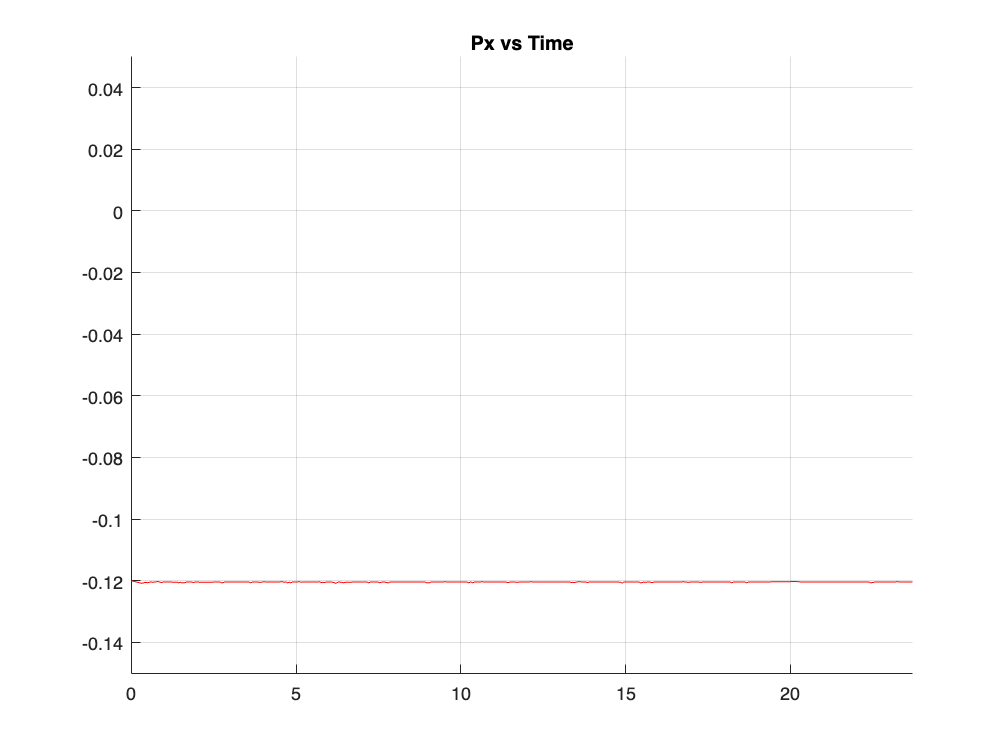


figure(1),clf,grid,hold on
title('Px vs Time')
plot(tGraph,XGraph,'r-')
axis([0 EKFTotalTime -0.15 0.05])

disp(Xk(1))

   -0.1204



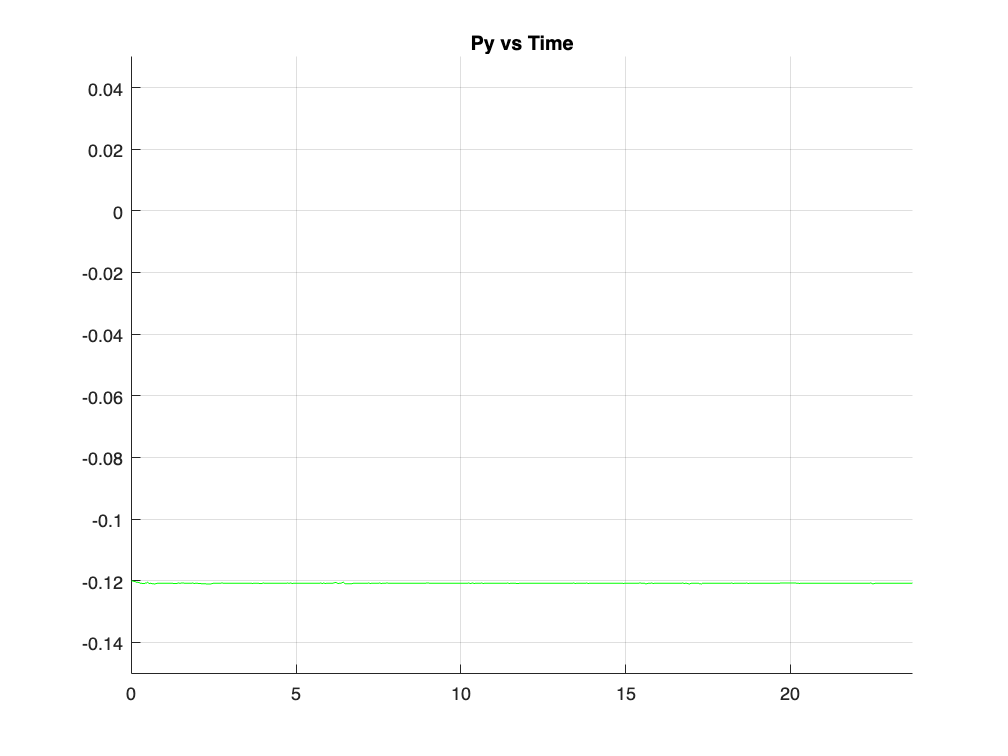


figure(2),clf,grid, hold on
title('Py vs Time')
plot(tGraph,YGraph,'g-')
axis([0 EKFTotalTime -0.15 0.05])

disp(Xk(2))

   -0.1209



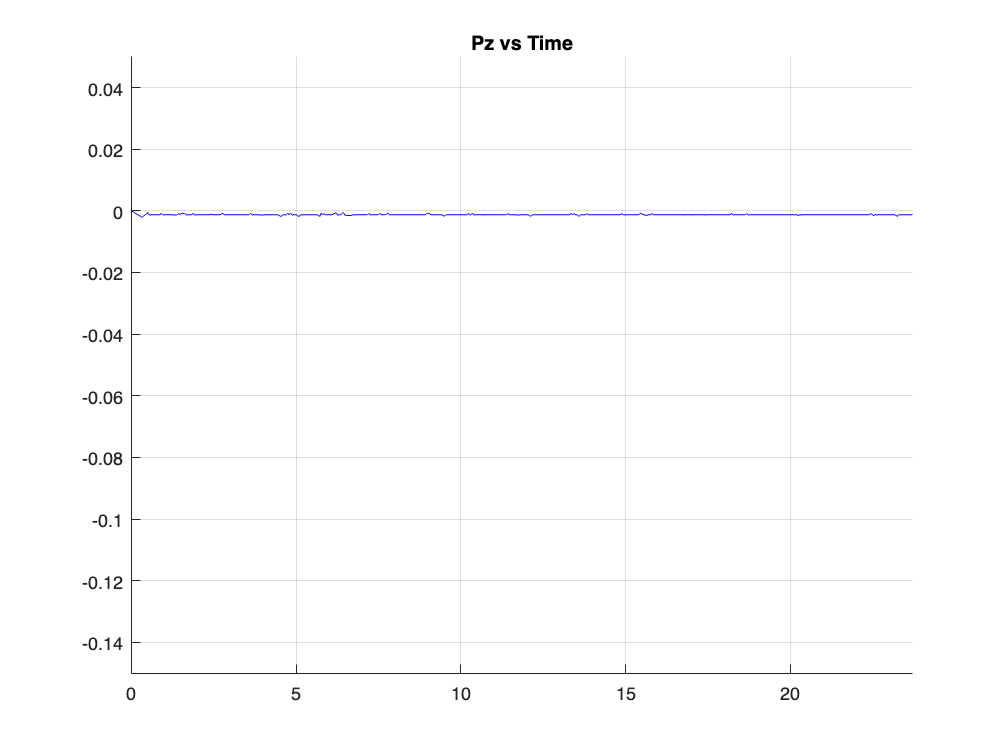


figure(3),clf,grid, hold on
title('Pz vs Time')
plot(tGraph,ZGraph,'b-')
axis([0 EKFTotalTime -0.15 0.05])

disp(Xk(3))

   -0.0013



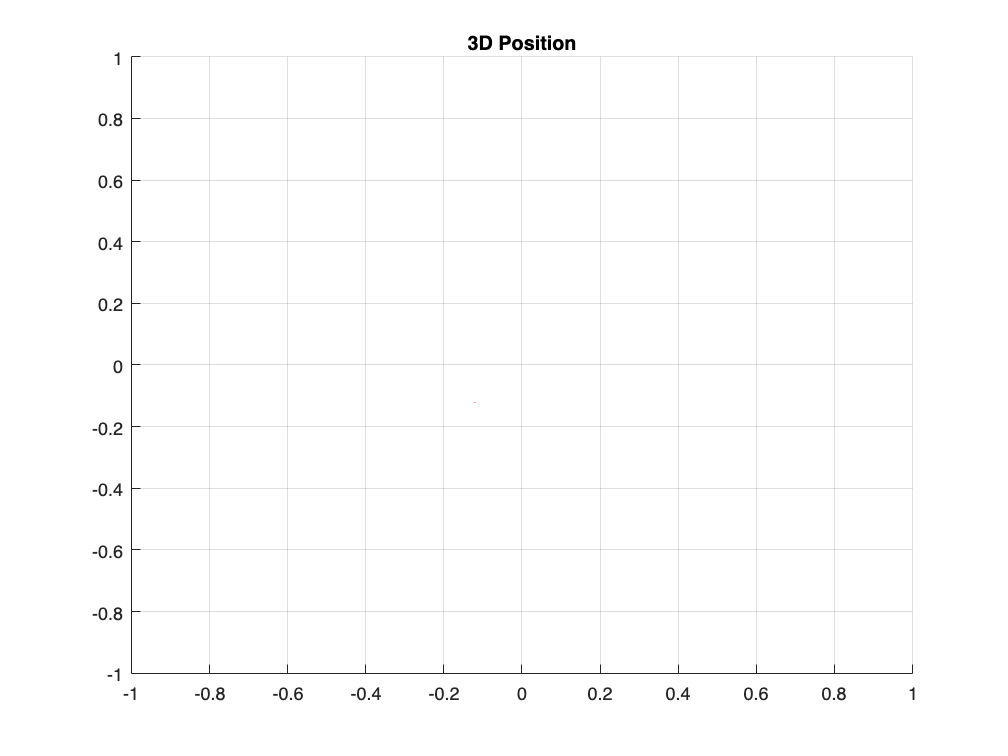


figure(4), clf, grid, hold on
plot3(XGraph,YGraph,ZGraph,'r-')
title('3D Position')
axis([-1 1 -1 1 -1 1])

Xk

Xk =    -0.1204
   -0.1209
   -0.0013
    0.0000
    0.0000
    0.0000


error = abs([Xk(1);Xk(2);Xk(3)] - [F4_B';0]) 

error =     0.0004
    0.0009
    0.0013


error_3D = sqrt((Xk(1)-F4_B(1))^2 + (Xk(2)-F4_B(2))^2 + (Xk(3)-0)^2)

error_3D = 0.0016

disp('in meters')

in meters


function error = computeReprojectionError(pose, worldPoints, imagePoints, cParams)
    % Decompose Pose Parameters
    rotationVector = pose(1:3);
    translationVector = pose(4:6);

    % Project World Points to Image Plane using estimated pose
    projectedPoints = world2img(worldPoints, rigidtform3d([eul2rotm(rotationVector) translationVector'; 0 0 0 1]), cParams.Intrinsics);

    % Compute Reprojection Error
    error = projectedPoints - imagePoints;
    error = error(:); % Reshape to a vector for lsqnonlin
end

function [UV, bOpenMV] = captureData(openmv,cameraParams)
    % Send a command to the camera to signal readiness
    openmv.write('READY','string');
    
    % Initialize output
    cam_data = [];
    bOpenMV = false; % Use 'false' instead of 'False' in MATLAB

    % Set a timeout for readline operation (adjust the timeout value as needed)
    openmv.Timeout = 1/500; % Timeout in seconds
    
    try 
        % Attempt to read data from the camera
        data_str = openmv.readline();
        % If data is successfully read, split and convert it to double
        cam_data = str2double(split(data_str,','));
        UV = undistortPoints([cam_data(1) cam_data(2)],cameraParams)';
        % If data is received, set boolean to true
        bOpenMV = true;
    catch 
        % Display error message
        % disp('Error occurred:');
        % disp(ME.message);
        UV = [];
        bOpenMV = false;
    end
end

function H_2rows = createH(C1,Xkp,isOpenMV)
    if isOpenMV
        H_2rows = [(C1(1,1)*C1(3,4) - C1(1,4)*C1(3,1) + C1(1,1)*C1(3,2)*Xkp(2) - C1(1,2)*C1(3,1)*Xkp(2) + C1(1,1)*C1(3,3)*Xkp(3) - C1(1,3)*C1(3,1)*Xkp(3))/((C1(3,4)+C1(3,1)*Xkp(1)+C1(3,2)*Xkp(2)+C1(3,3)*Xkp(3))^2) C1(1,2)*C1(3,4) - C1(1,4)*C1(3,2) - C1(1,1)*C1(3,2)*Xkp(1) + C1(1,2)*C1(3,1)*Xkp(1) + C1(1,2)*C1(3,3)*Xkp(3) - C1(1,3)*C1(3,2)*Xkp(3)/((C1(3,4)+C1(3,1)*Xkp(1)+C1(3,2)*Xkp(2)+C1(3,3)*Xkp(3))^2) C1(1,3)*C1(3,4) - C1(1,4)*C1(3,3) - C1(1,1)*C1(3,3)*Xkp(1) + C1(1,3)*C1(3,1)*Xkp(1) - C1(1,2)*C1(3,3)*Xkp(2) + C1(1,3)*C1(3,2)*Xkp(2)/((C1(3,4)+C1(3,1)*Xkp(1)+C1(3,2)*Xkp(2)+C1(3,3)*Xkp(3))^2) 0 0 0;
                   (C1(2,1)*C1(3,4) - C1(2,4)*C1(3,1) + C1(2,1)*C1(3,2)*Xkp(2) - C1(2,2)*C1(3,1)*Xkp(2) + C1(2,1)*C1(3,3)*Xkp(3) - C1(2,3)*C1(3,1)*Xkp(3))/((C1(3,4)+C1(3,1)*Xkp(1)+C1(3,2)*Xkp(2)+C1(3,3)*Xkp(3))^2) C1(2,2)*C1(3,4) - C1(2,4)*C1(3,2) - C1(2,1)*C1(3,2)*Xkp(1) + C1(2,2)*C1(3,1)*Xkp(1) + C1(2,2)*C1(3,3)*Xkp(3) - C1(2,3)*C1(3,2)*Xkp(3)/((C1(3,4)+C1(3,1)*Xkp(1)+C1(3,2)*Xkp(2)+C1(3,3)*Xkp(3))^2) C1(2,3)*C1(3,4) - C1(2,4)*C1(3,3) - C1(2,1)*C1(3,3)*Xkp(1) + C1(2,3)*C1(3,1)*Xkp(1) - C1(2,2)*C1(3,3)*Xkp(2) + C1(2,3)*C1(3,2)*Xkp(2)/((C1(3,4)+C1(3,1)*Xkp(1)+C1(3,2)*Xkp(2)+C1(3,3)*Xkp(3))^2) 0 0 0;];
    else
        H_2rows = [];
    end
end

function R = createR(b1,b2,b3,b4,b5,b6)
    n=0;
    if b1
        n=n+1;
    end
    if b2
        n=n+1;
    end
    if b3
        n=n+1;
    end
    if b4
        n=n+1;
    end
    if b5
        n=n+1;
    end
    if b6
        n=n+1;
    end
    R = eye(2*n);
end

function HXkp = createHXkp(Xkp, extrinsics, cameraParams, isOpenMV)
    if isOpenMV
        HXkp = world2img(Xkp(1:3)',rigidtform3d(extrinsics),cameraParams)';
    else
        HXkp = [];
    end
end